# DL draft

(Section 4)

github@hnxj; github@dynasim

## 0. Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Modeling\'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## 1.Neural circuit structure in Dynasim

PINH: Pyramidal-INterneuron Harmony circuit.

study_dir = 'dlModels/PN15';

eqns={
  ['dV/dt = (Iapp*rand(1, N_pop)*(cos(t*omega).^2)*((t > t0) & (t < t1)))' ...
  ' + @current + noise*randn(1, N_pop); noise = 0; t0 = 550; t1 = 950; omega = .12;' ...
  ' Iapp = 0; V(0) = -50*rand(1, N_pop);']
};
% Control current drive for direct stimulation purposes

nEx = 36;
nIl = 7;
nIg = 7;

% nRti = ceil(nIl/nEx);

gGABAslow = 0.25; % Receptor conductances, will be modulated by synaptic conn.
gGABAfast = 0.25;
gAMPAfar = 0.25;

gGABA = 0.25;
gAMPA = 0.25;
tauGain = 25;

% All receptor synaptic decay time constants are from the same dist. 
tauGABAslow = tauGain*(1 + .1*randn(1)); % SST->~20Hz ~(1/2t = 1/100)
tauGABAfast = tauGain*(1 + .1*randn(1)); % PV->~20Hz (1/10)
tauAMPAnear = tauGain*(1 + .1*randn(1)); % PY->~20.0Hz (1/20)
tauAMPAfar = tauGain*(1 + .1*randn(1)); % PY->~20.0Hz (1/40)

iNoise = 50;
eNoise = iNoise*1.0;
fNoise = iNoise*1.0;
sNoise = iNoise*1.0;

% gleakEx = 0.001;
% gleakIl = 0.001;
% gleakIg = 0.001;

cCoeff = 1.0;
cCoeffx = 1.0;
cConst = 0.1;

kEE = rand(nEx, nEx) * cCoeffx + cConst;
kEIf = rand(nEx, nIl) * cCoeff + cConst;
kEIs = rand(nEx, nIg) * cCoeff + cConst;

kIfE = rand(nIl, nEx) * cCoeff + cConst;
kIfIf = rand(nIl, nIl) * cCoeffx + cConst;
kIfIs = rand(nIl, nIg) * cCoeff + cConst;

kIsE = rand(nIg, nEx) * cCoeff + cConst;
kIsIf = rand(nIg, nIl) * cCoeff + cConst;
kIsIs = rand(nIg, nIg) * cCoeffx + cConst;

s=[];
s.populations(1).name='EXc';
s.populations(1).size=nEx;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK', 'ileak'};
s.populations(1).parameters={'gNa',120,'gK',36,'noise',eNoise};

s.populations(2).name='INl';
s.populations(2).size=nIl;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK', 'ileak'};
s.populations(2).parameters={'gNa',120,'gK',36,'noise',fNoise};

s.populations(3).name='INg';
s.populations(3).size=nIg;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK', 'ileak'};
s.populations(3).parameters={'gNa',120,'gK',36,'noise',sNoise};

s.connections(1).direction='INl->EXc';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfE};

s.connections(2).direction='EXc->INl';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPAnear,'gAMPA',gAMPAfar, 'netcon', kEIf};

s.connections(3).direction='INg->EXc';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsE};

s.connections(4).direction='EXc->INg';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPAfar,'gAMPA',gAMPAfar, 'netcon', kEIs};

s.connections(5).direction='INg->INl';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIf};

s.connections(6).direction='INg->INg';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD', tauGABAslow,'gGABAa',gGABA, 'netcon', kIsIs};

s.connections(7).direction='INl->INg';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIs};

s.connections(8).direction='INl->INl';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABA, 'netcon', kIfIf};

s.connections(9).direction='EXc->EXc';
s.connections(9).mechanism_list={'iAMPA'};
s.connections(9).parameters={'tauD',tauAMPAnear,'gAMPA',gAMPA, 'netcon', kEE};

RunDuration = 1500; % In ms (miliseconds) 
vary = {'Iapp', [0 50]};

tic;
data = dsSimulate(s, 'tspan', [0 RunDuration], 'downsample_factor', 10, ...
                     'dt', .1, 'study_dir', '/dlSim/dlSim28', ...
                     'compile_flag', 0, 'parallel_flag', 0, ...
                     'vary', vary, 'verbose_flag', 0);
toc;

Elapsed time is 17.729956 seconds.


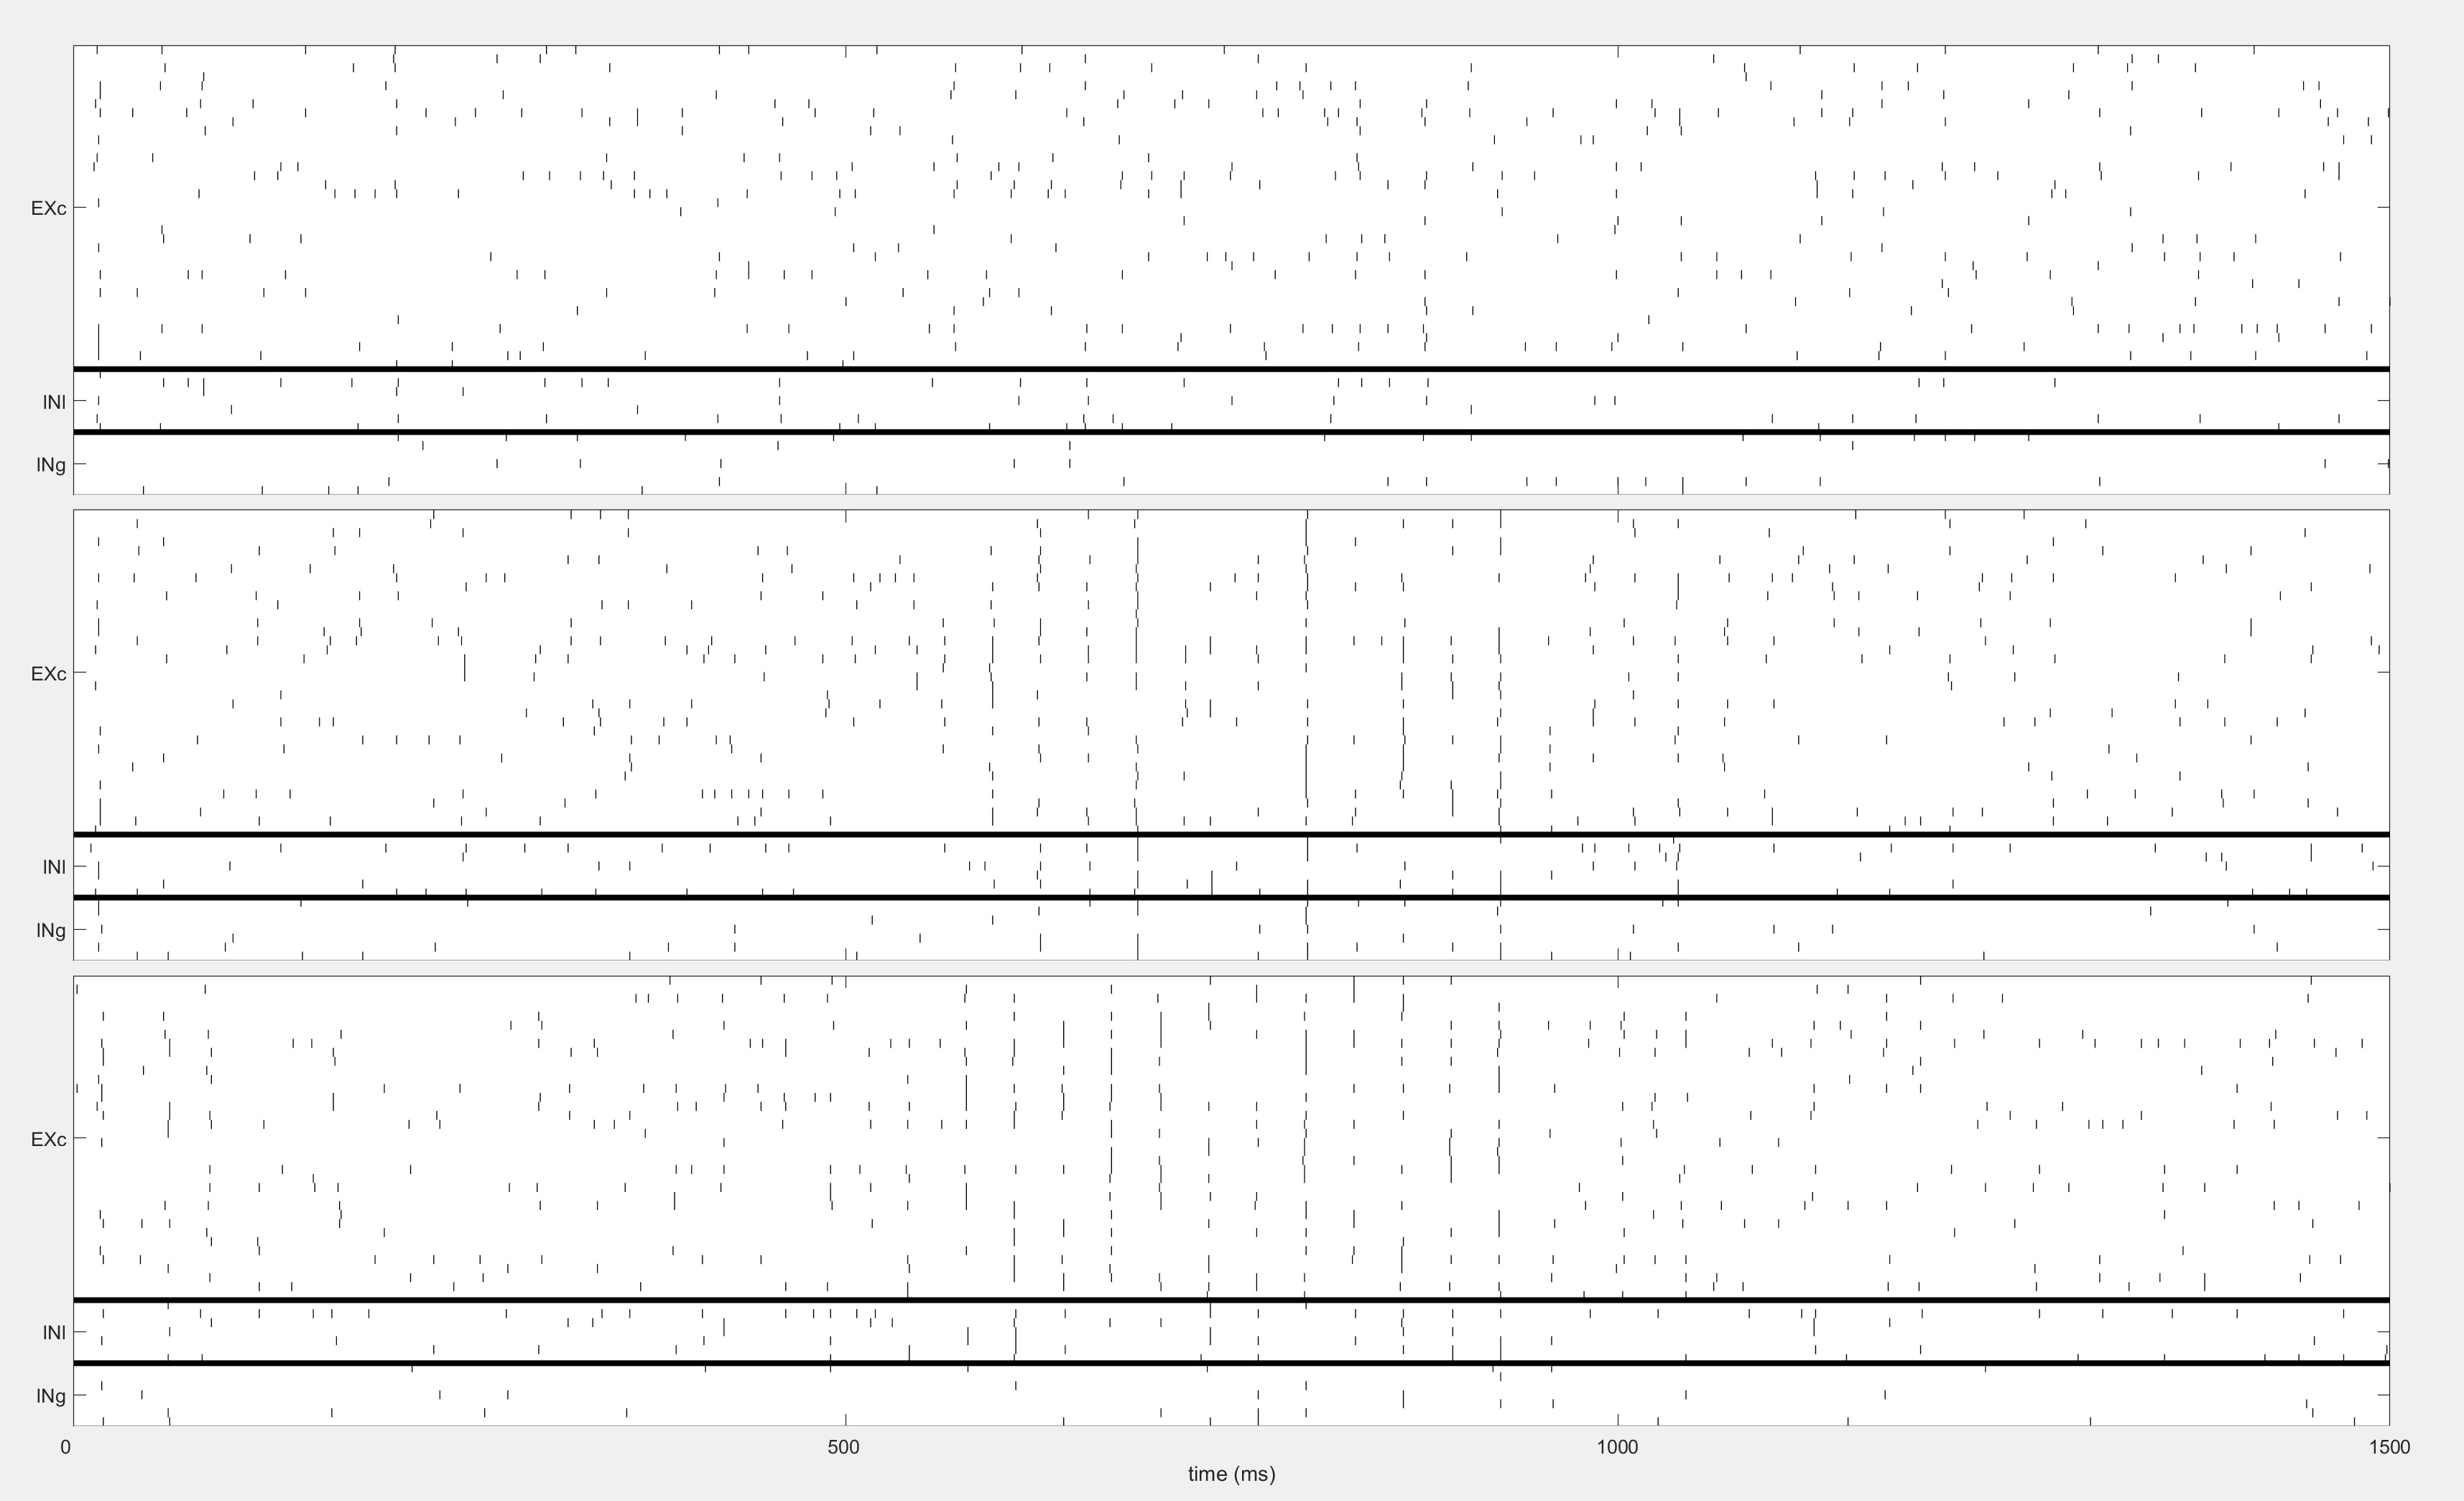

dsPlot(data, 'plot_type', 'raster', 'threshold', -10);

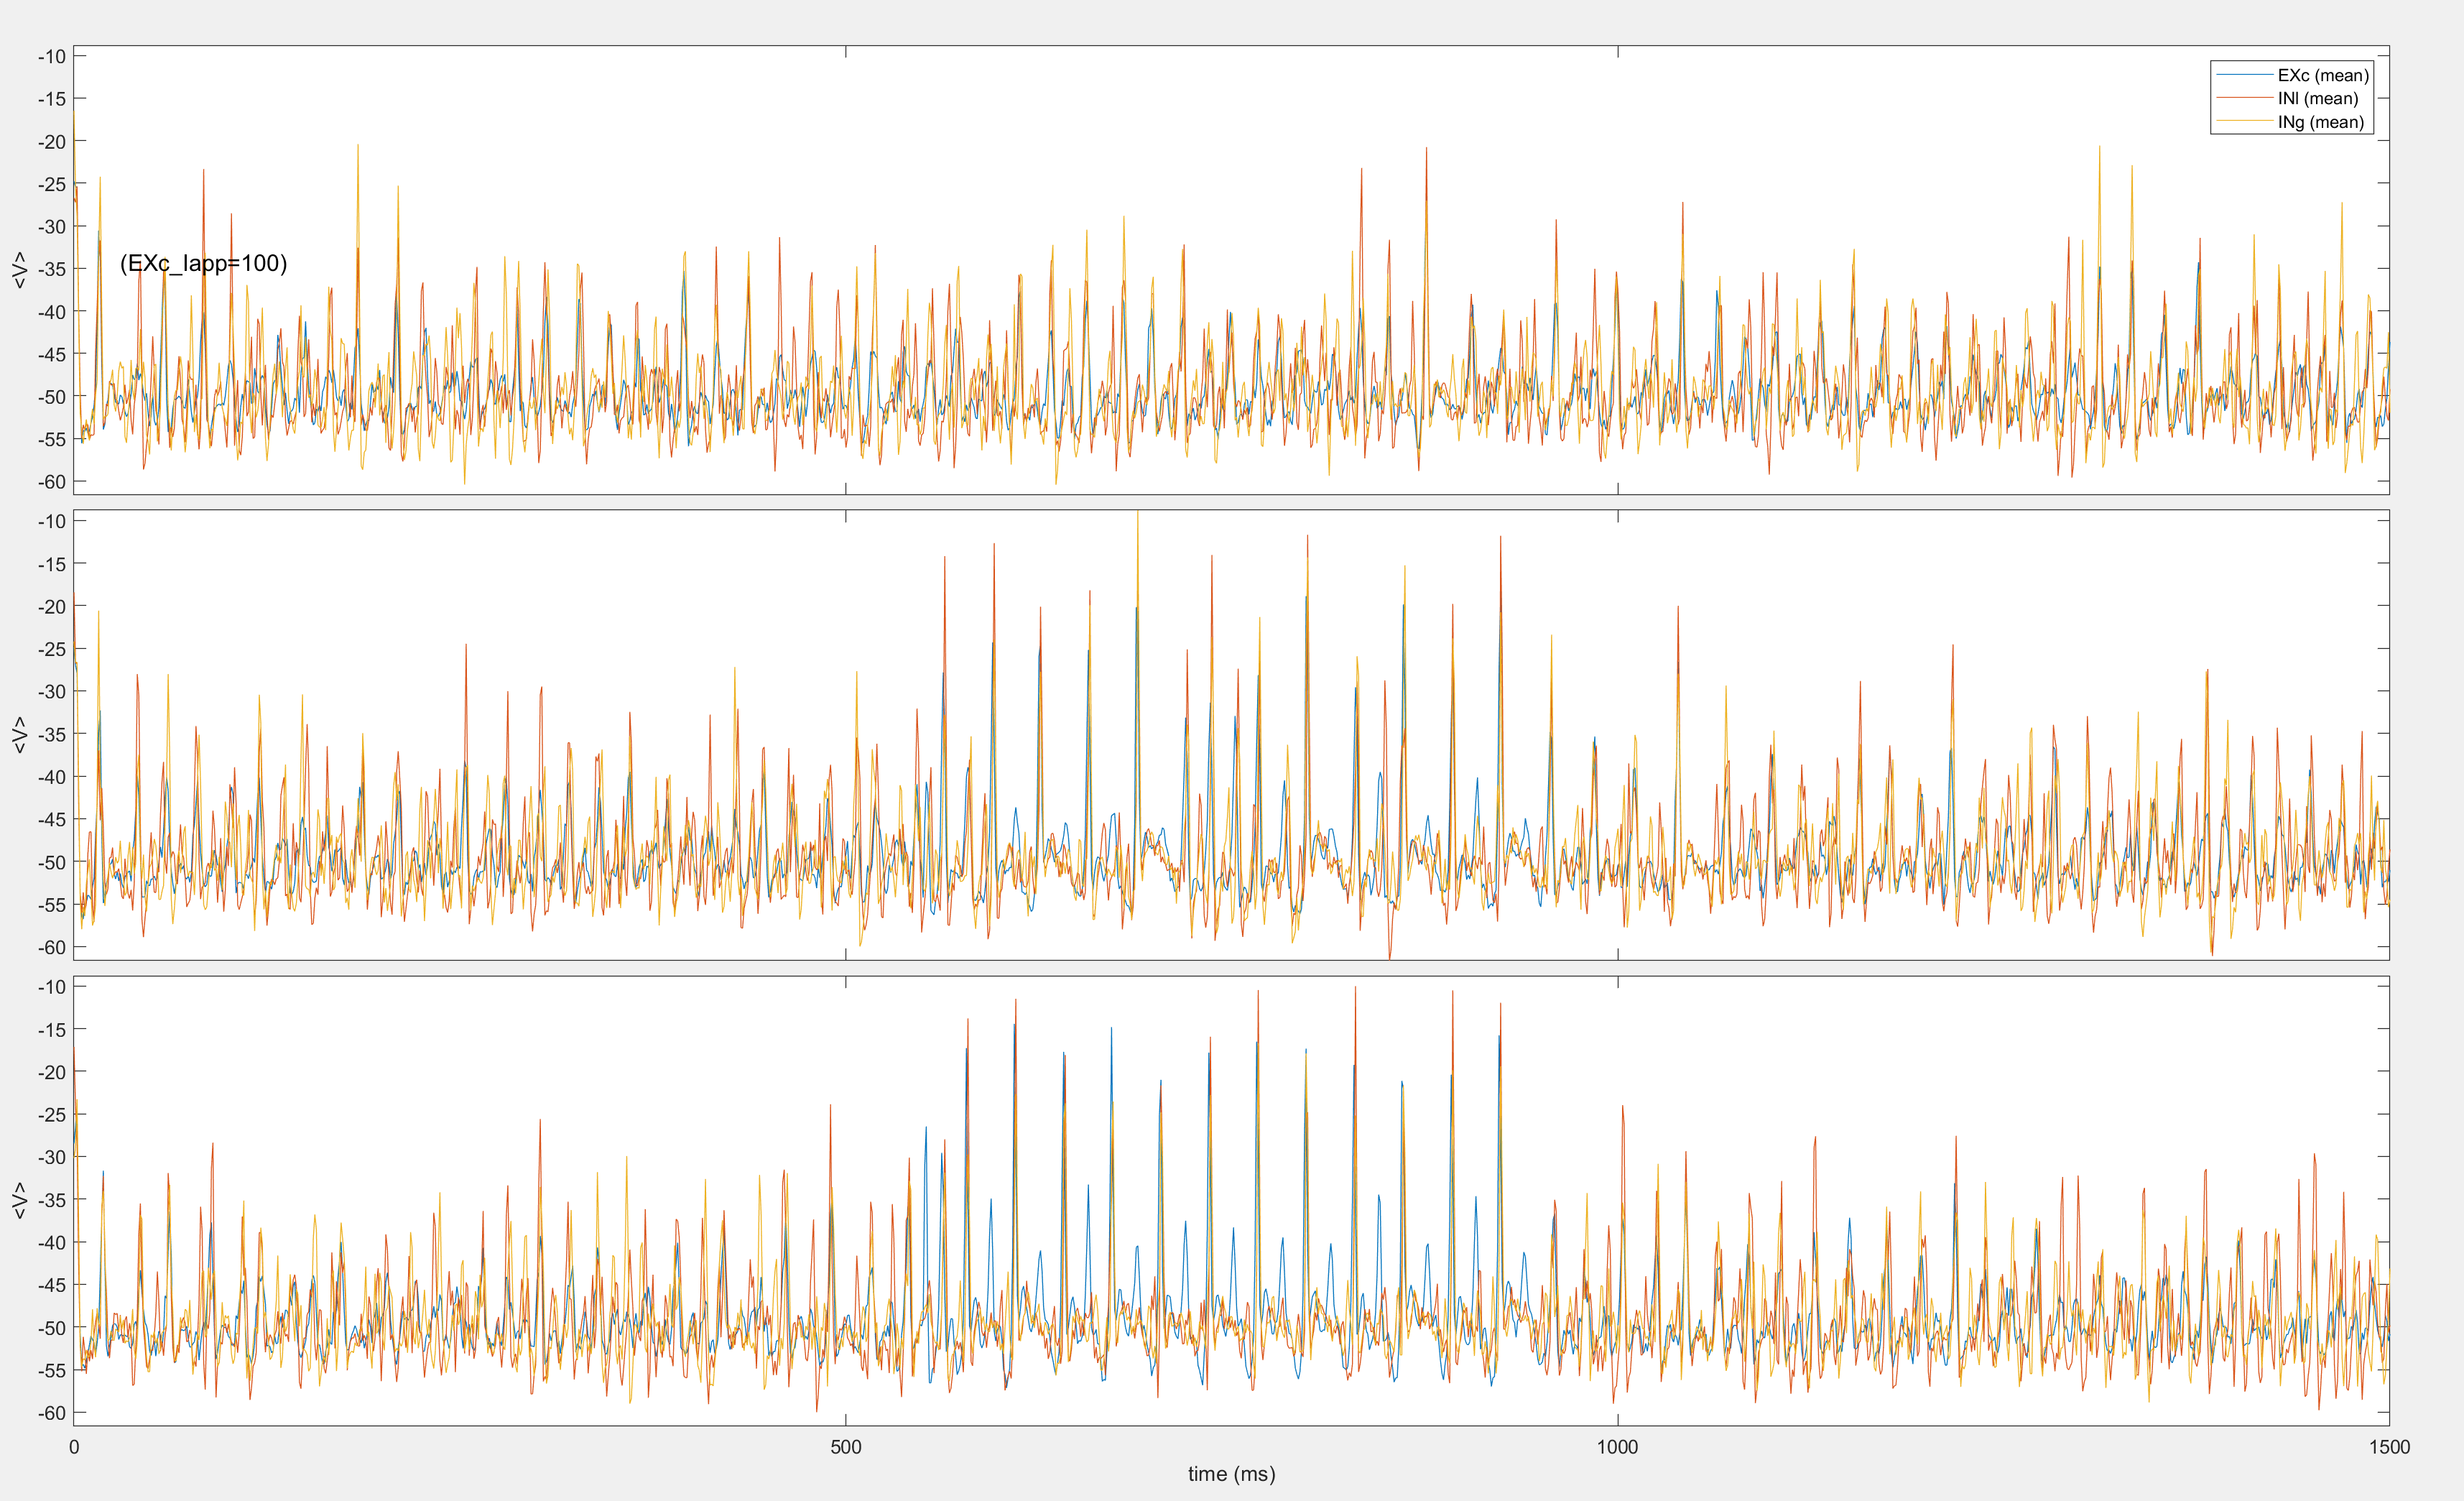

dsPlot(data, 'plot_type', 'waveform');

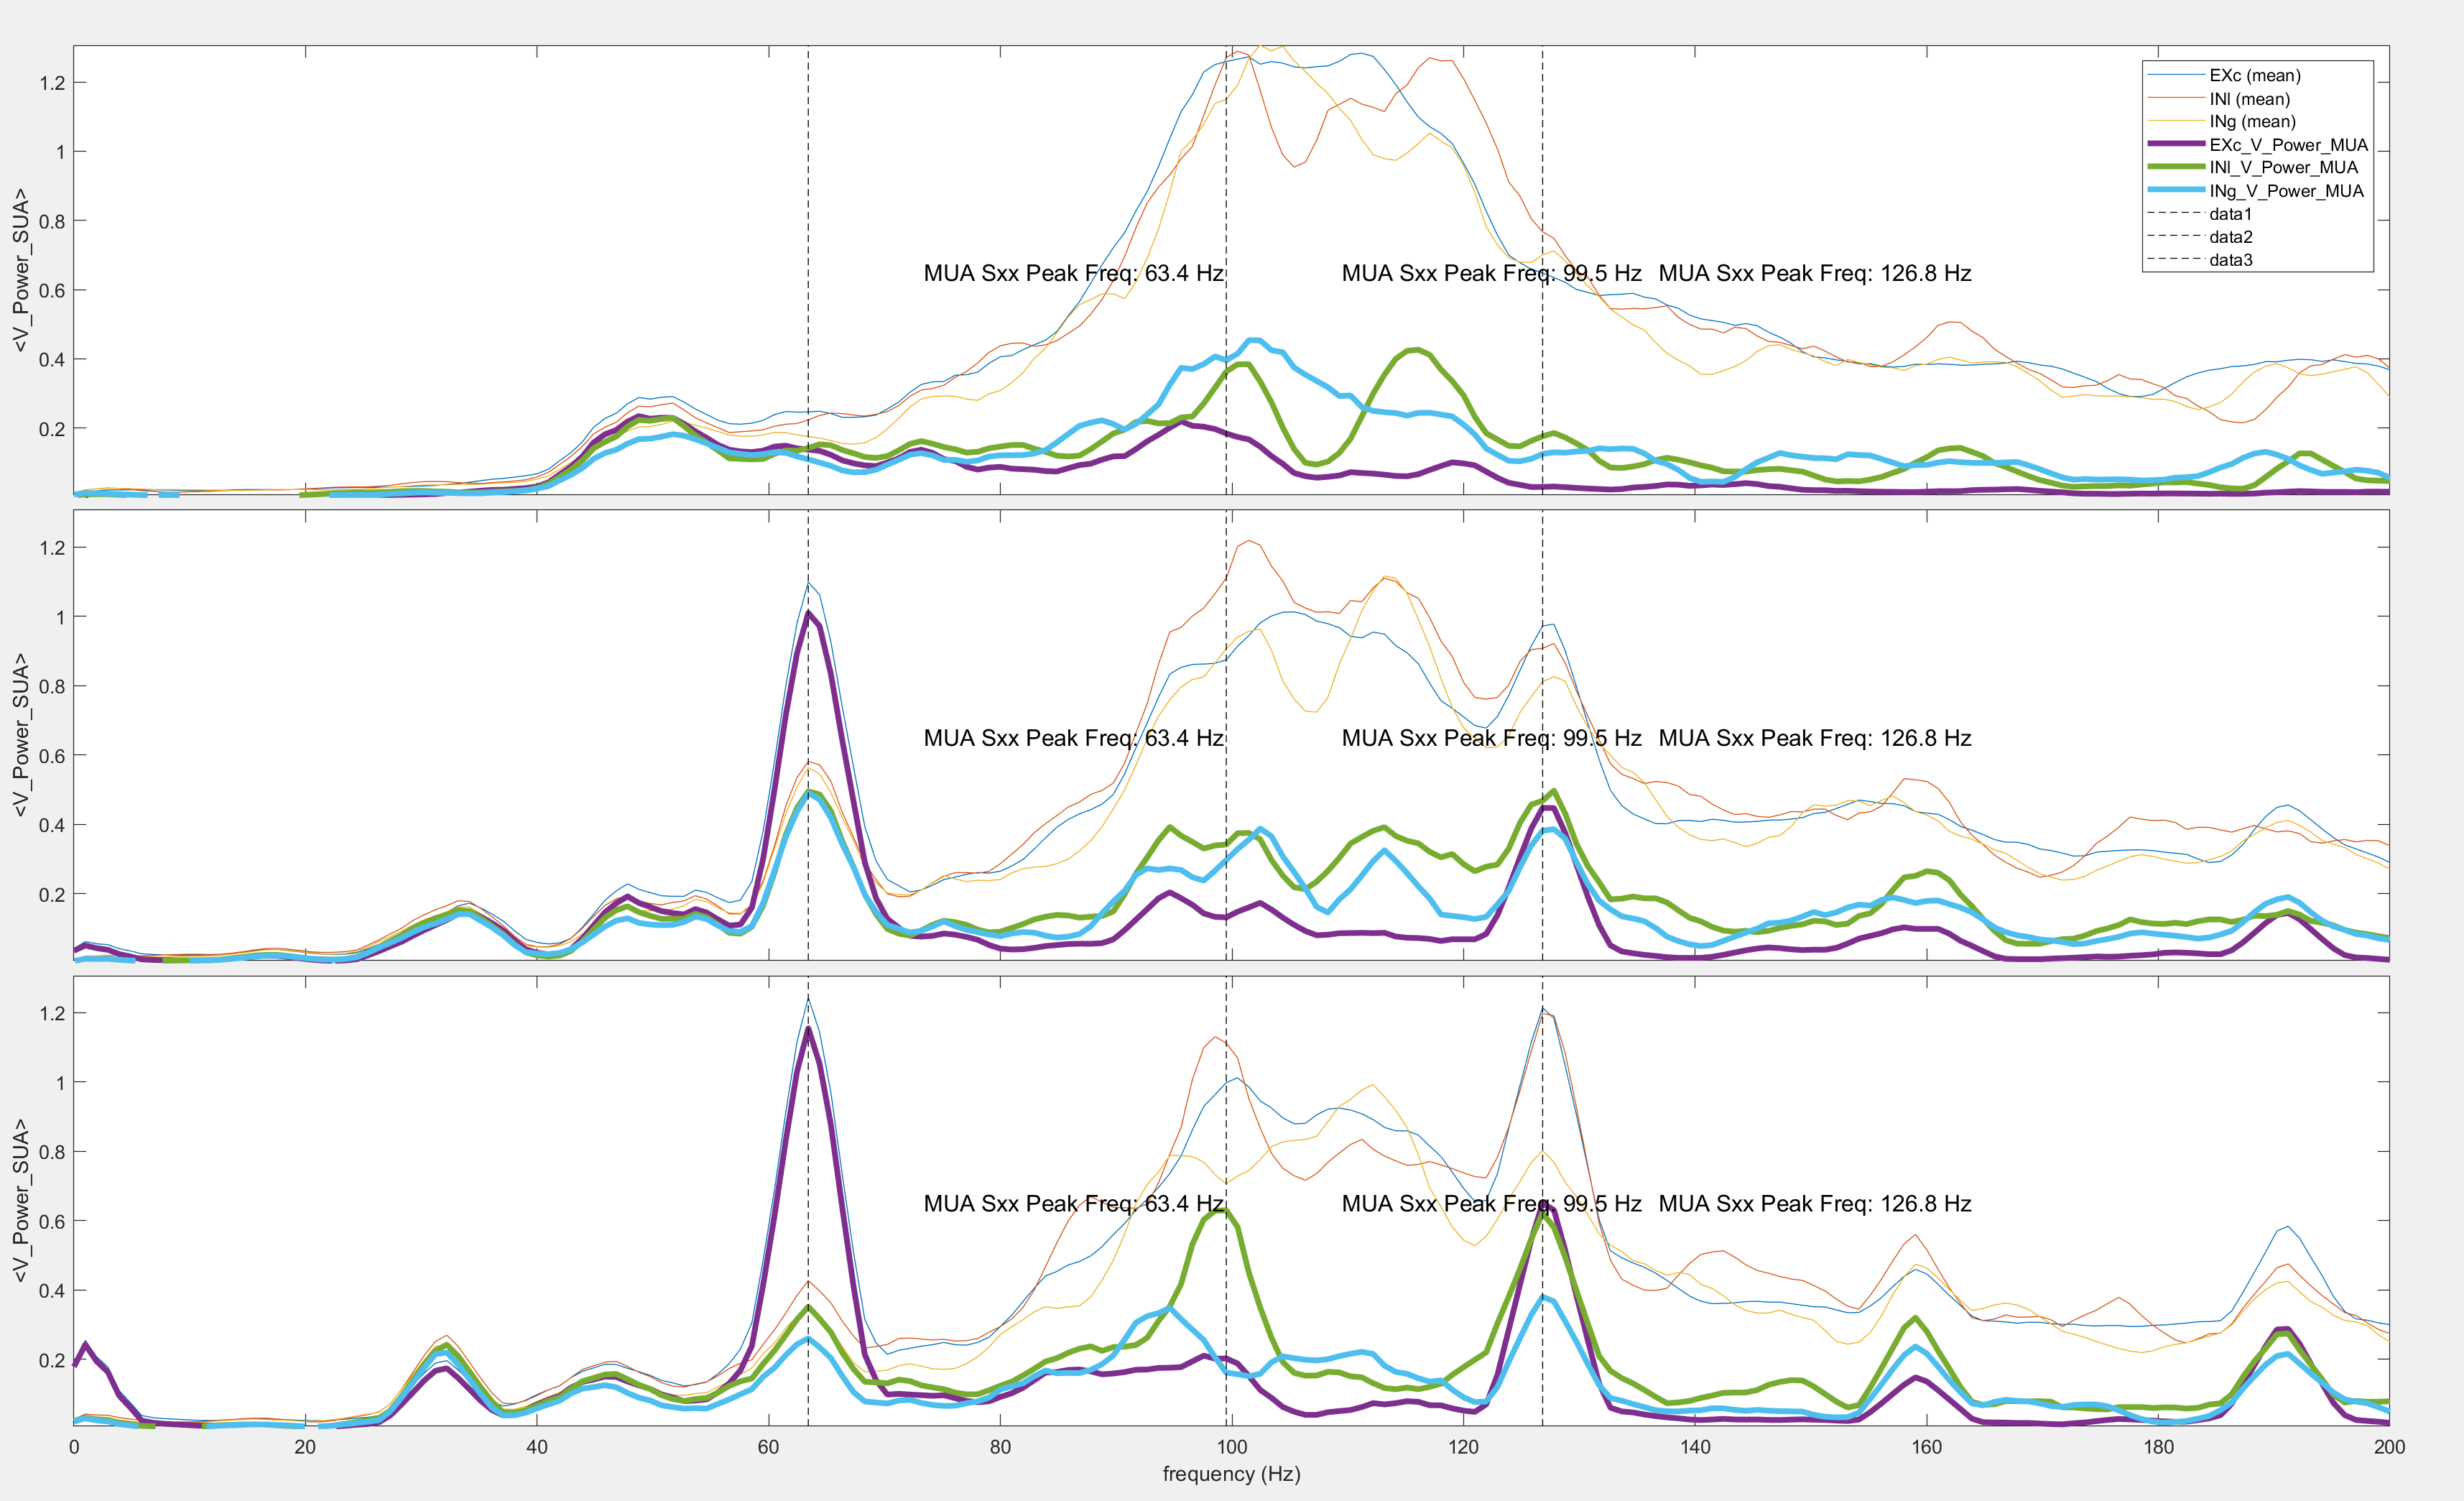

dsPlot(data, 'plot_type', 'power');

## 2. DynaLearn object initialization

dl = DynaLearn(s, study_dir, 'mex', 'PN', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Modeling\DynaSim\dlModels\PN15
Creating data directory: D:\Modeling\DynaSim\dlModels\PN15\data
Creating results directory: D:\Modeling\DynaSim\dlModels\PN15\results
saving study file: D:\Modeling\DynaSim\dlModels\PN15\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Creating solver directory D:\Modeling\DynaSim\dlModels\PN15\solve\sim1
Changing directory to D:\Modeling\DynaSim\dlModels\PN15\solve\sim1
Saving params.mat
Creating solver file: D:\Modeling\DynaSim\dlModels\PN15\solve\sim1\solve_ode_20250129173219_362.m
Compiling file: D:\Modeling\DynaSim\dlModels\PN15\solve\sim1\solve_ode_20250129173219_362.m
  


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/PN15/dlFile.mat".


- Loader function; if the model already exists.

id = 14;
dl = DynaLearn.dlLoader(char("dlModels/PN" + num2str(id)));

DL object loaded from dlModels/PN14 
Params.mat file loaded from dlModels/PN14 
--------
--->Constructing graph ... Done.

Reinitialized.


x = load("matdata\PoGLO_Ca_0818_MTMST.mat").y;
x = x.sigsb2l;

% trial = 2;
a = squeeze(mean(mean(x(1:4, 31:77, 301:2200), 1), 1));
ax = x(:, 31:77, 301:2200);
a = detrend(a);

[b, f, t] = pspectrum(mean(a, 1), 1000, "spectrogram", ...
    "FrequencyLimits", [0 100], "TimeResolution", 0.5, "OverlapPercent", 98);
b = zeros(size(b));

for ik = 1:size(ax, 1)

    for jk = 1:size(ax, 2)

        at = squeeze(ax(ik, jk, :));
        at = detrend(at);
        [bt, ~, ~] = pspectrum(at, 1000, "spectrogram", ...
            "FrequencyLimits", [0 100], "TimeResolution", 0.5, "OverlapPercent", 98);

        b = b + bt;

    end

end


% subplot(2, 1, 1);
% imagesc(b, "XData", t, "YData", f);colormap("jet");
% colorbar();
% clim([0 1e-5])

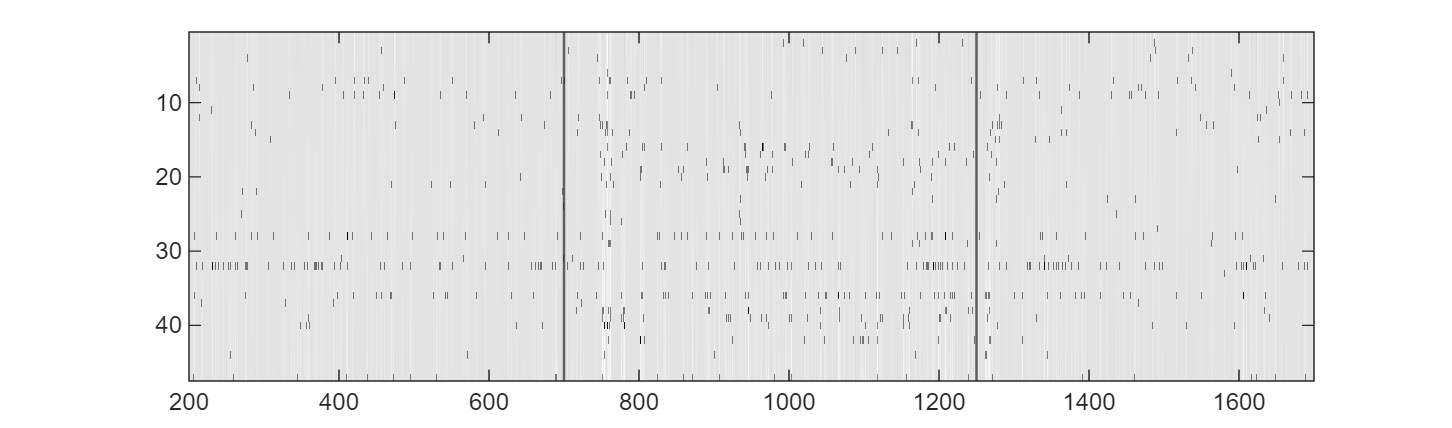

targetVsgram = b;

for ik = 1:size(targetVsgram, 1)

    targetVsgram(ik, :) = targetVsgram(ik, :);

end

targetVsgram = (targetVsgram - min(min(targetVsgram)));
targetVsgram = (targetVsgram / max(max(targetVsgram)));

% targetVsgram = sqrt(targetVsgram);

figure("Position", [0 0 1700 500]);
subplot(1, 1, 1);
imagesc(1-a);colormap("gray");xline(700, "LineWidth", 1);xline(1250, "LineWidth", 1);
xlim([200 1700]);

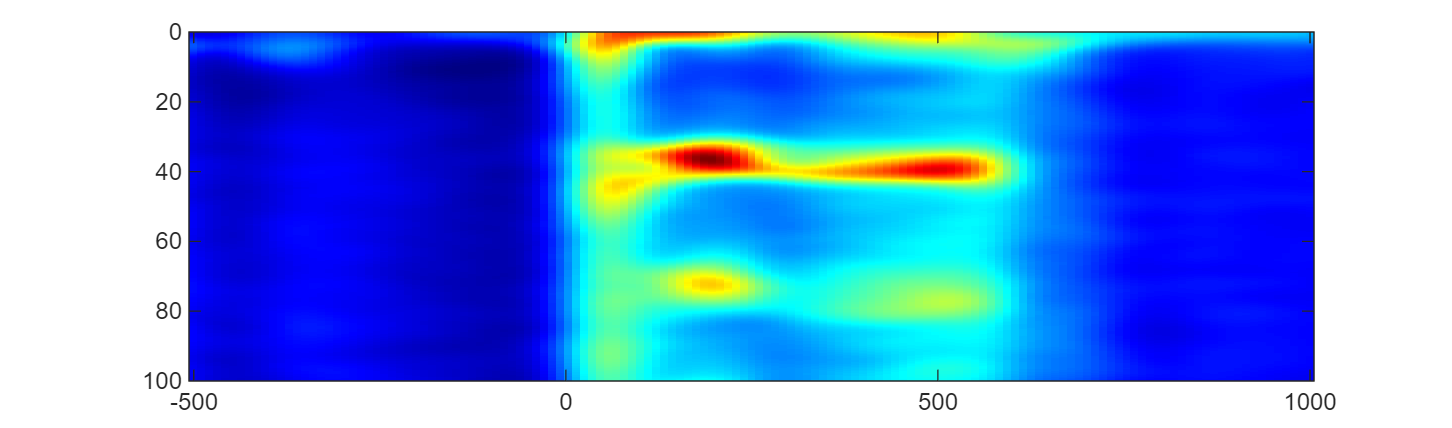


figure("Position", [0 0 1700 500]);
subplot(1, 1, 1);
imagesc(targetVsgram, "XData", -501:1000, "YData", f);
clim([0 1.0]);colormap("jet");%xline(0, "LineWidth", 2);xline(550, "LineWidth", 2);

targetVsgram1 = targetVsgram(:, end-40:end);
targetVsgram2 = targetVsgram;

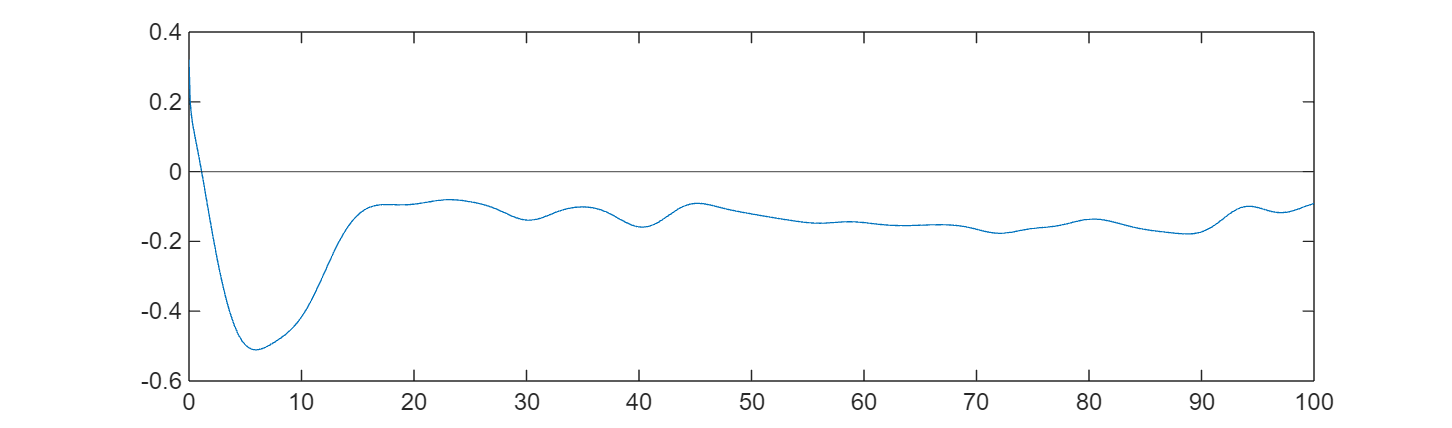

a1 = mean(targetVsgram(:, 1:22), 2);
a2 = mean(targetVsgram(:, 23:44), 2);
plot(linspace(0, 100, length(a1)), (a2-a1)./a1);
yline(0);

RunDuration = 1500;

[inp1, inp2] = dlOnOffInputs(RunDuration, 550, 950, 15);
dlInputParameters = {inp2}; % Null inputs (no external stimulation).
dlOutputParameters = {['EXc', '_V'], 1:36, [1 RunDuration], 'afr'};
dlTargetParameters = {{{'LogCor2', 1, targetVsgram2, 1.0, 1, 100}; {'MXE', 1, 10, 1.0, 0, 0}}};

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure

dlTrainOptions('dlBatchs') = 1;
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations
dlTrainOptions('dlUpdateVerbose') = 1;

dlTrainOptions('dlExcludeDiverge') = 1; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 5;
dlTrainOptions('dlTrainIncludeList') = ["_netcon"];
dlTrainOptions('dlUpdateMode') = 'Batch';

% dlTrainOptions('dlTrainRestrictList') = "_netcon"; % Restrict list
% dlTrainOptions('dlTrainRestrictCoef') = {0.01}; % Restrict coeffs
% dlTrainOptions('dlTrainRestrictBound') = {[0.2 10.0]};

dlTrainOptions('dlTrainExcludeList') = "_IC_noise";
% dlTrainOptions('dlTrainSyncList') = ["EXc_noise", "INl_noise", "INg_noise"];
dlTrainOptions('dlMIDP') = 0;
dlTrainOptions('dlCheckpointCoefficient') = 2.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-->Log flag for loss plot is not specified; default = 1.


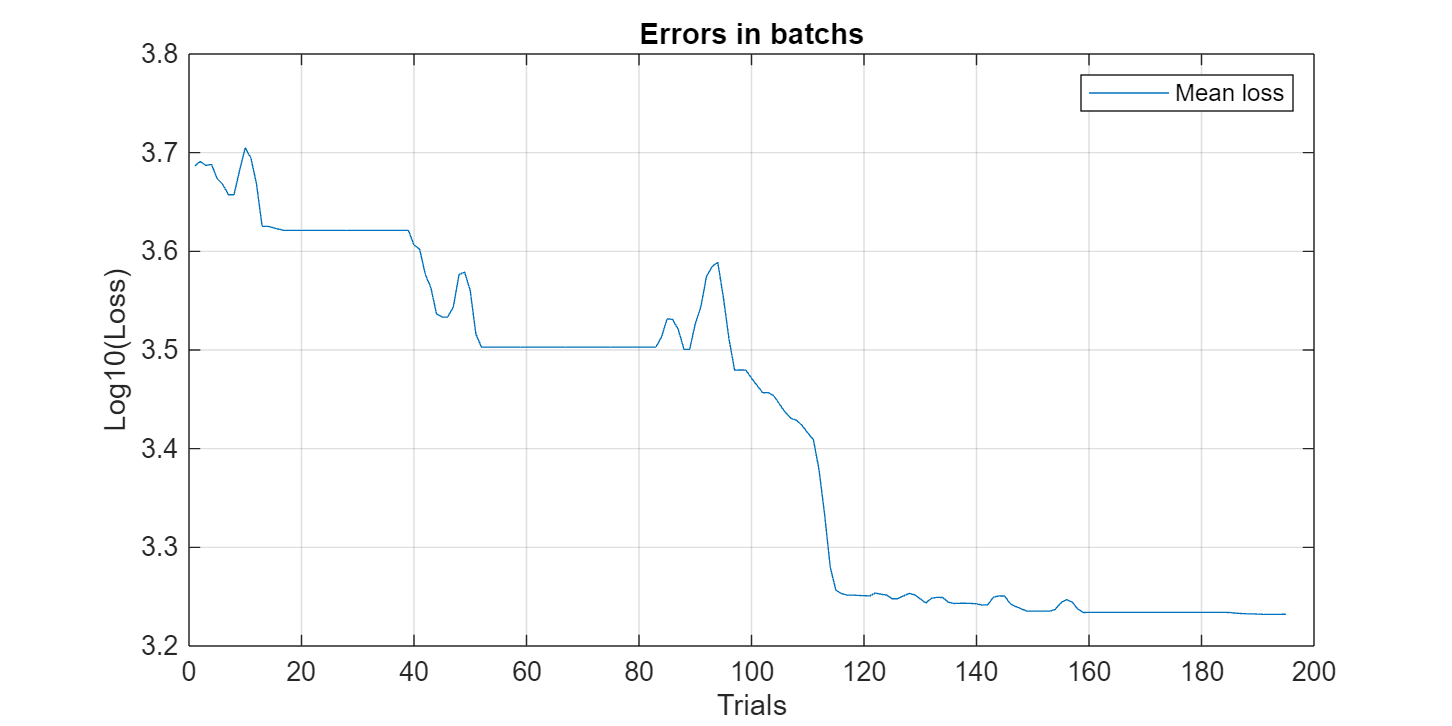

dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/PN14/Optimal 
---->Optimal [Parallel]


Condition Iapp = 0



	->Single trial running: 
Updating parameters of dlModels/PN14/solve > 

	->Done.


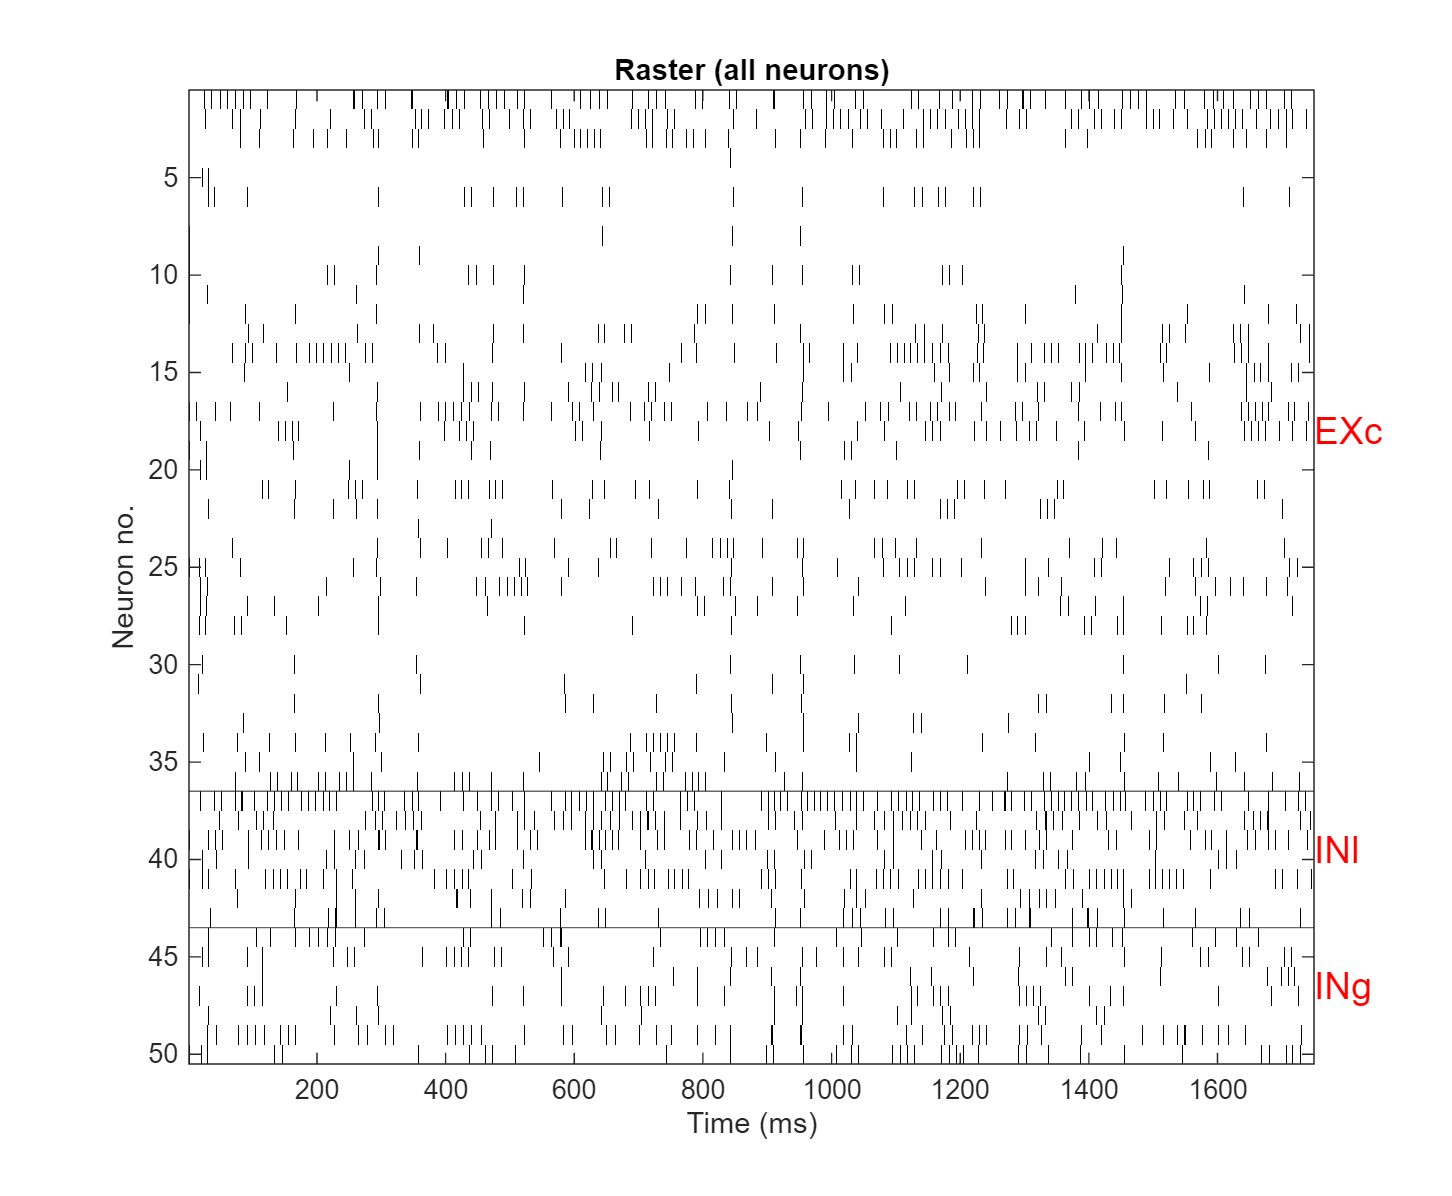

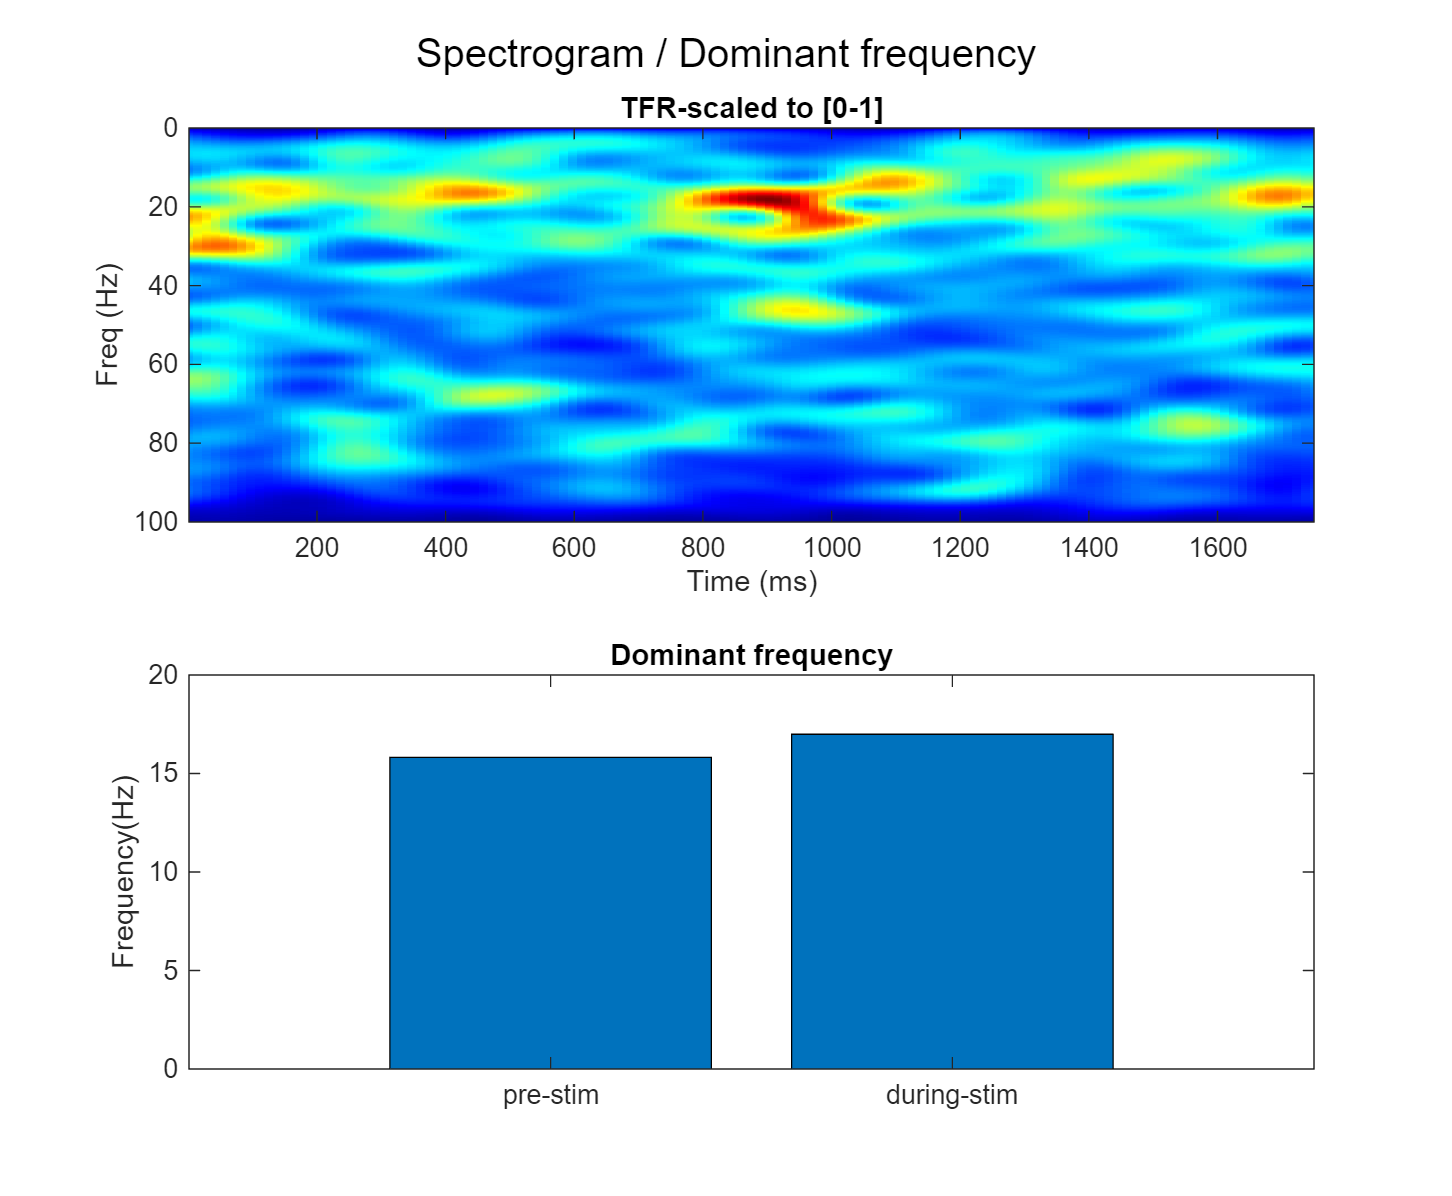

Condition Iapp = 6.6667



	->Single trial running: 
Updating parameters of dlModels/PN14/solve > 

	->Done.


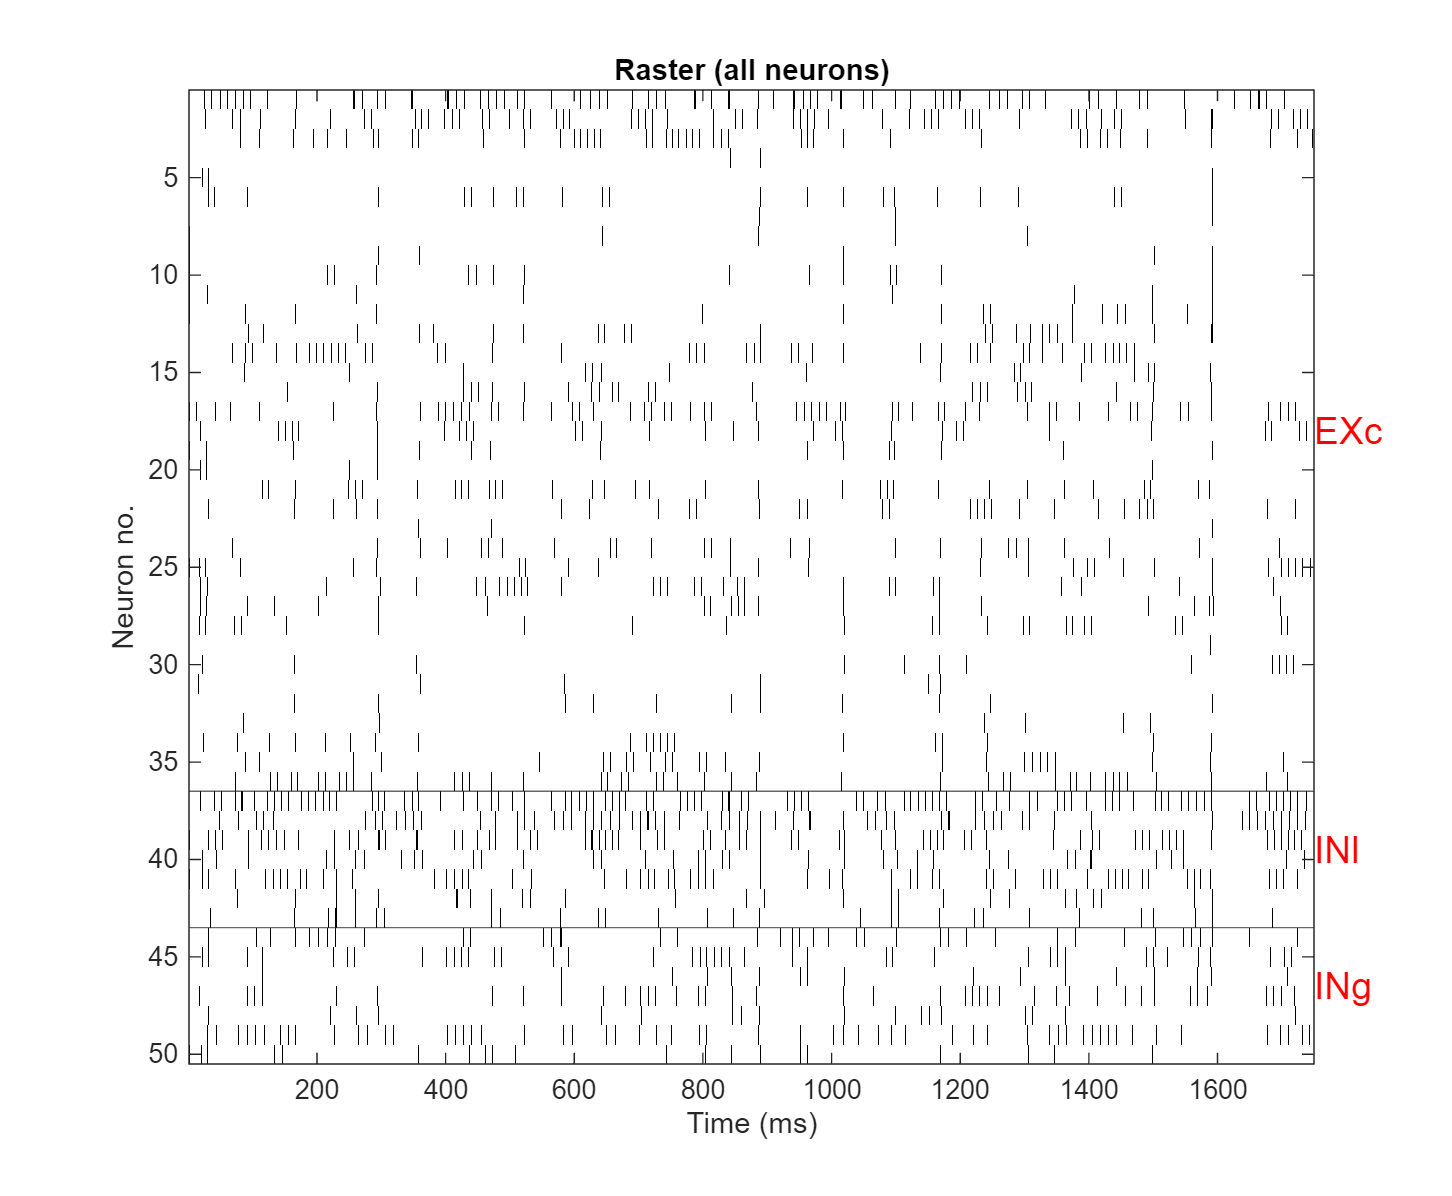

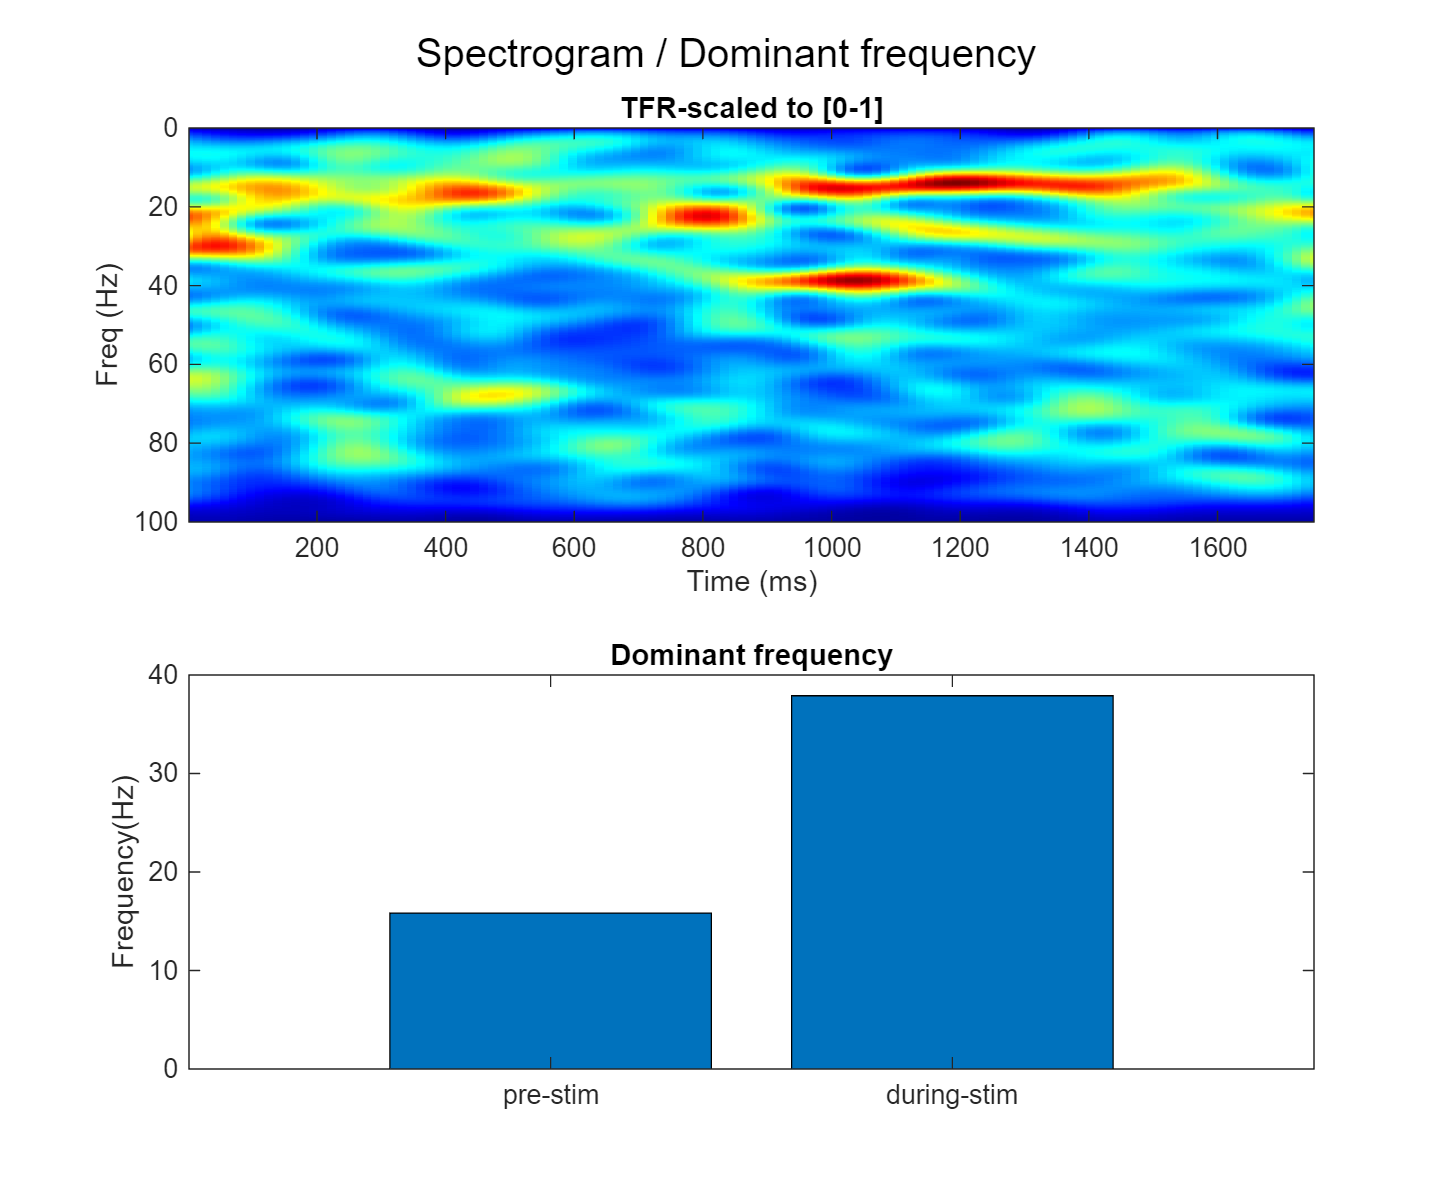

Condition Iapp = 13.3333



	->Single trial running: 
Updating parameters of dlModels/PN14/solve > 

	->Done.


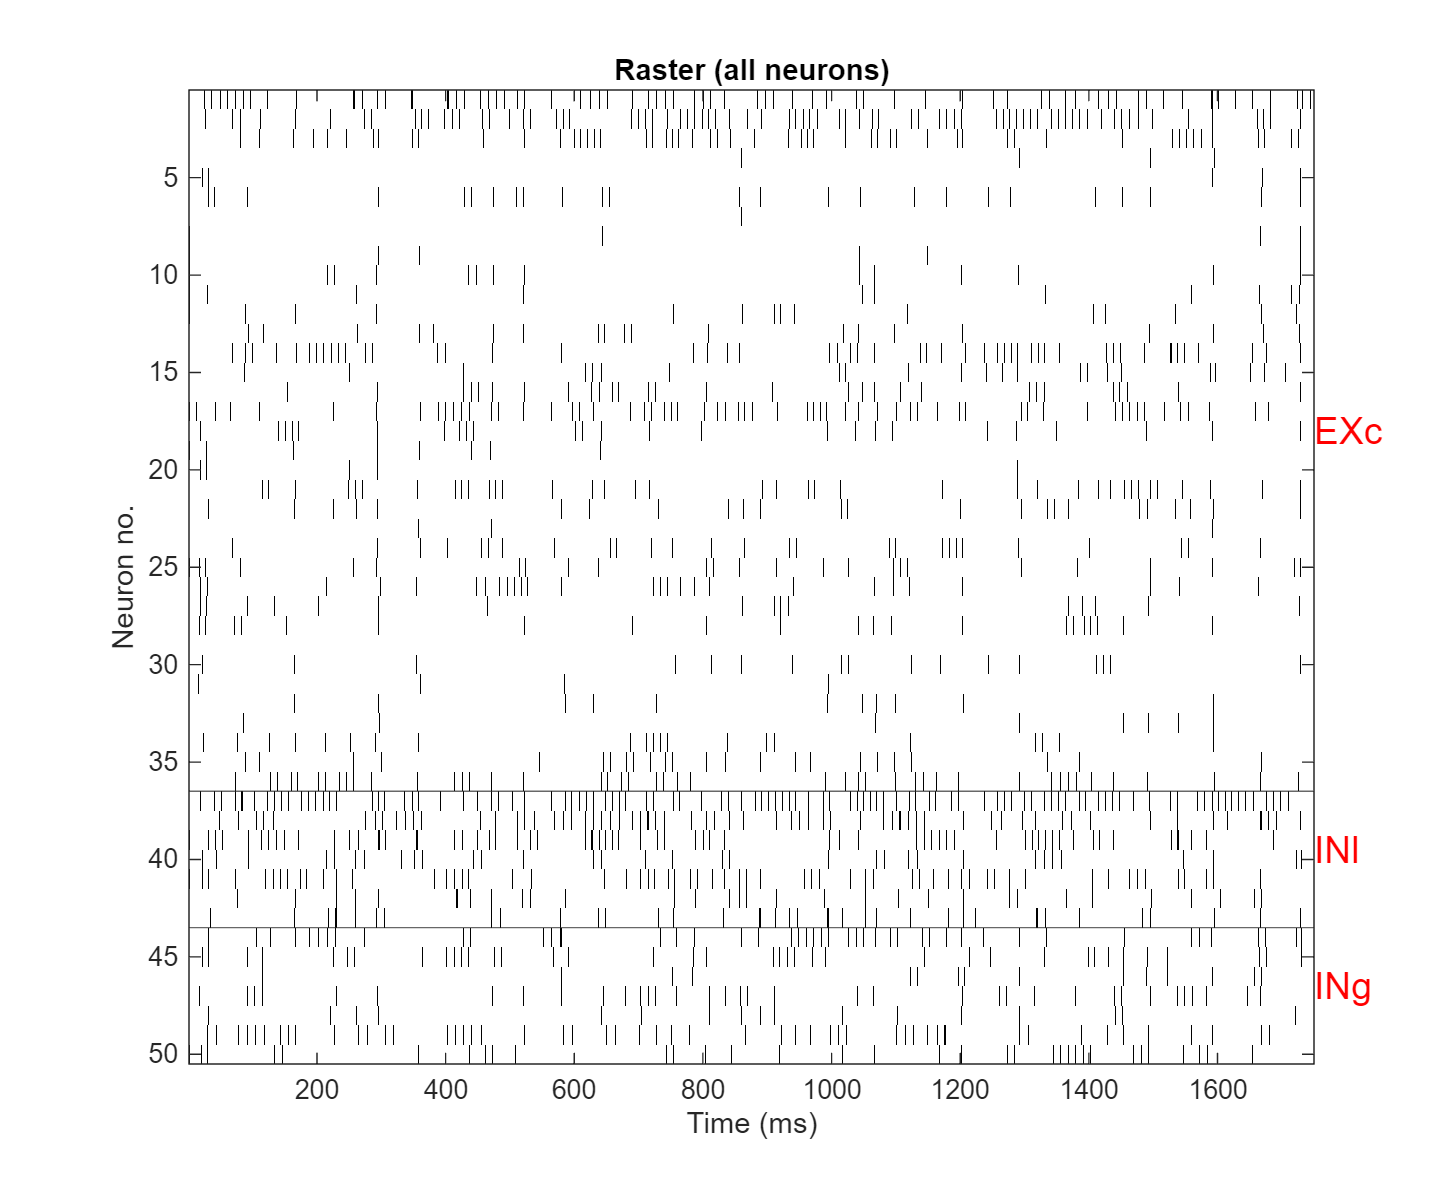

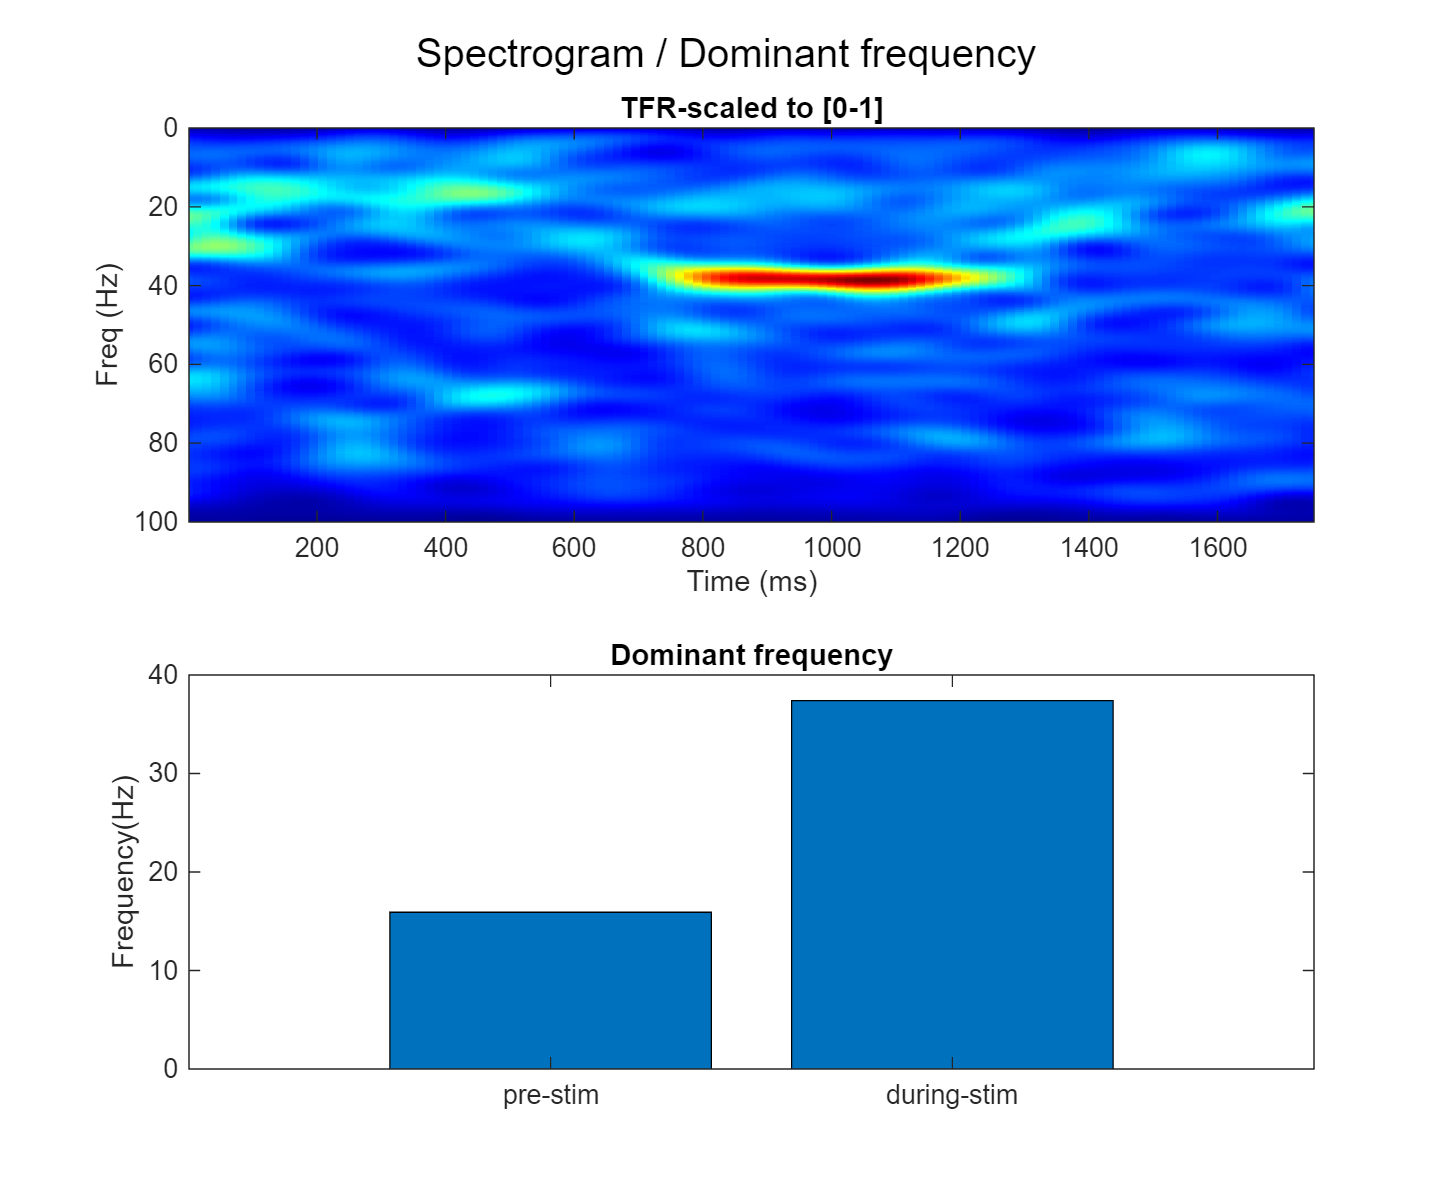

RunDuration = 1750;
ng = 4;
dlInputParameters2 = dlGradedInputs(RunDuration, 750, 1150, 20, ng);

xlims = [1 1750];
clims = [0 1.0];

for i = 1:ng%max(size(dlInputParameters, 2))

    disp("Condition Iapp = " + num2str(dlInputParameters2{i}("EXc_Iapp")));
    dl.dlRunSimulation(dlInputParameters2{i});%, dlOutputParameters);
    dl.dlRaster(xlims, -20);
    dl.dlSpectrogram(200, 1, 190, 100, xlims, clims);

end

Condition Iapp = 0



	->Single trial running: 
Updating parameters of dlModels/PN15/solve > 

	->Done.


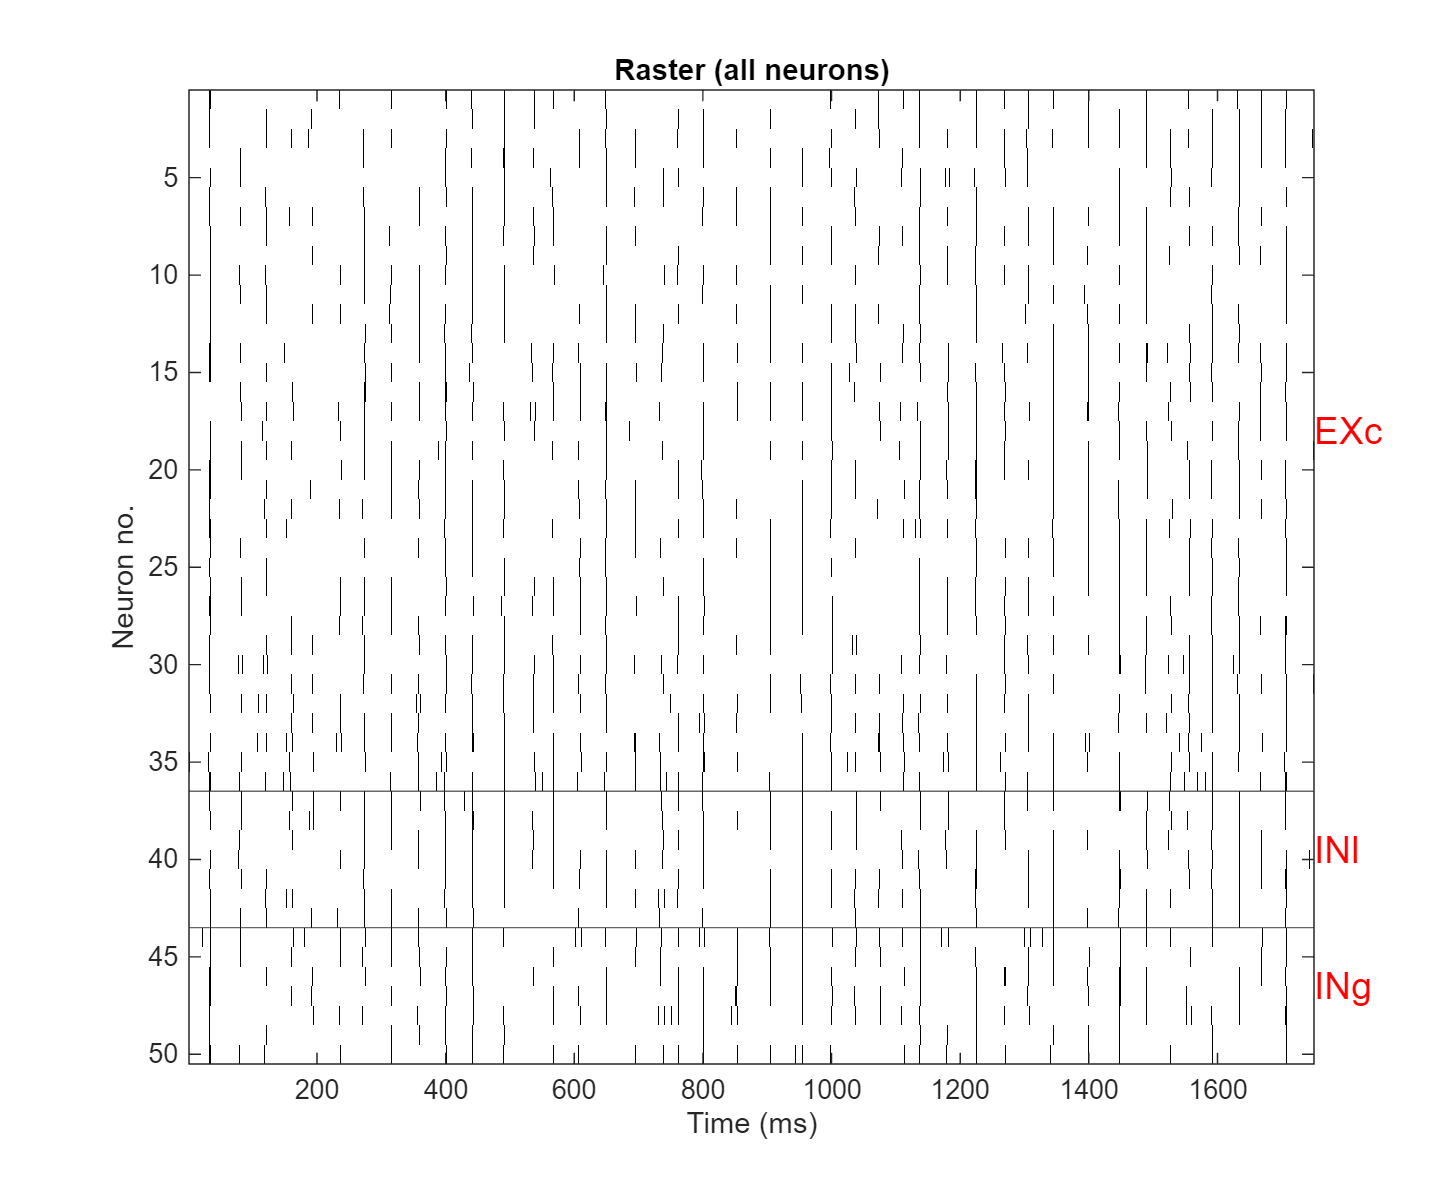

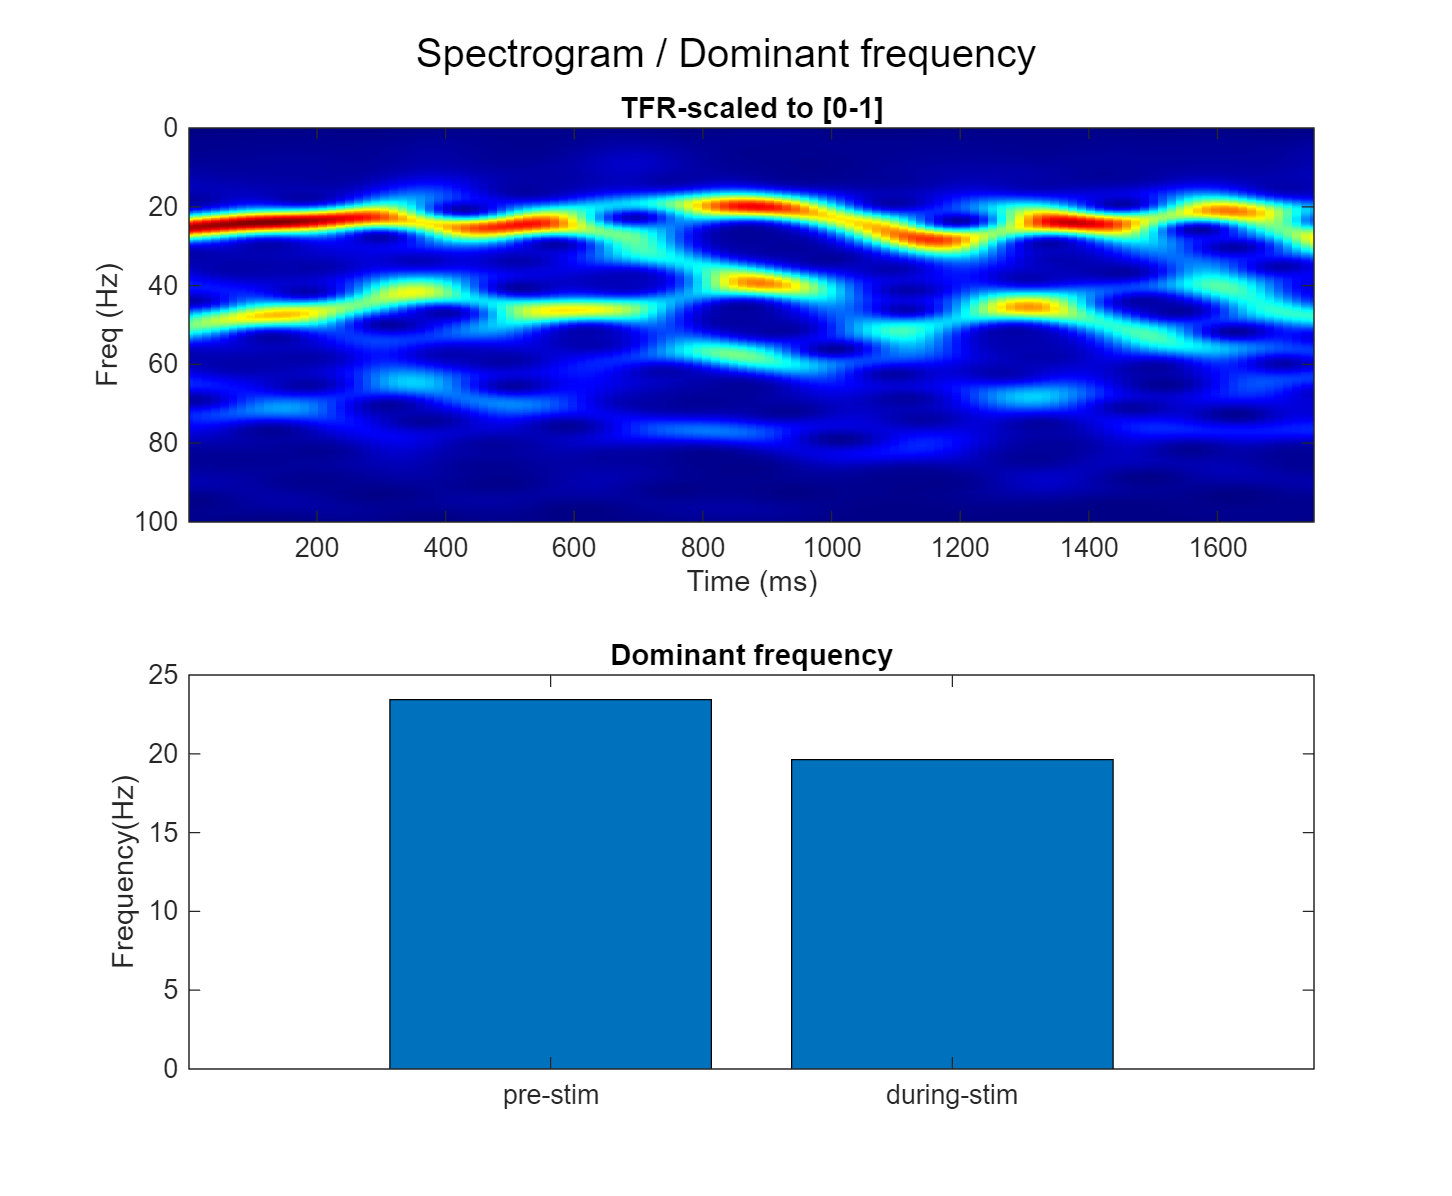

Condition Iapp = 6.6667



	->Single trial running: 
Updating parameters of dlModels/PN15/solve > 

	->Done.


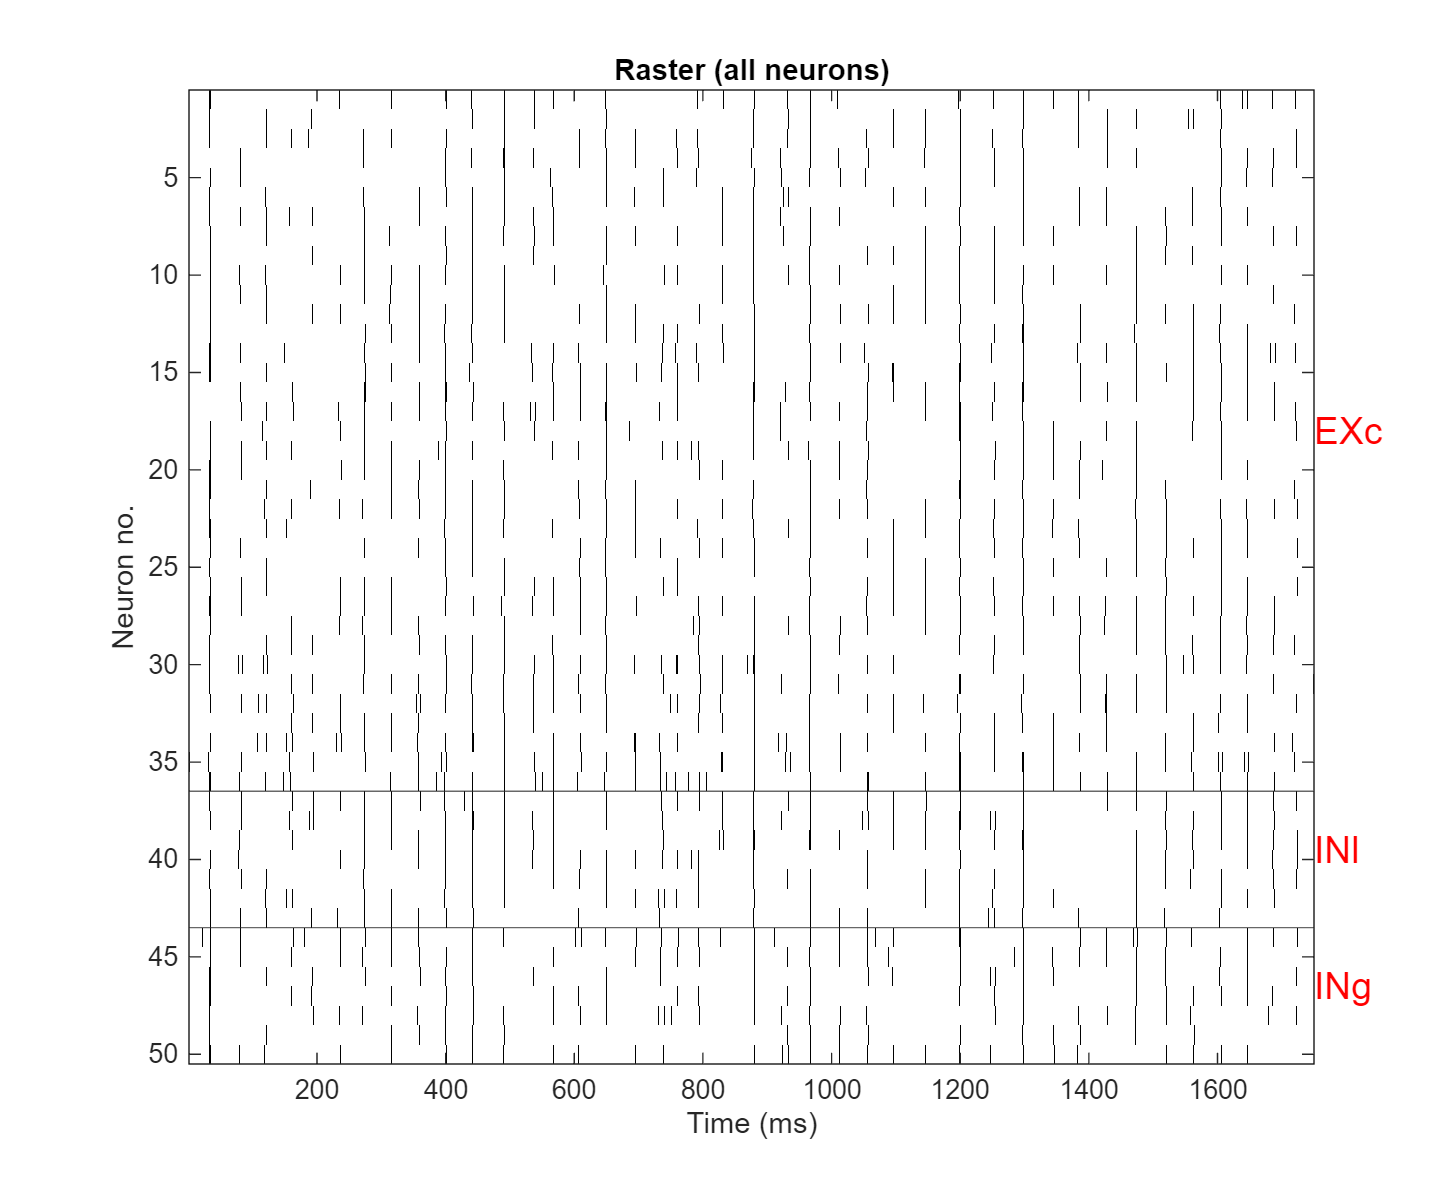

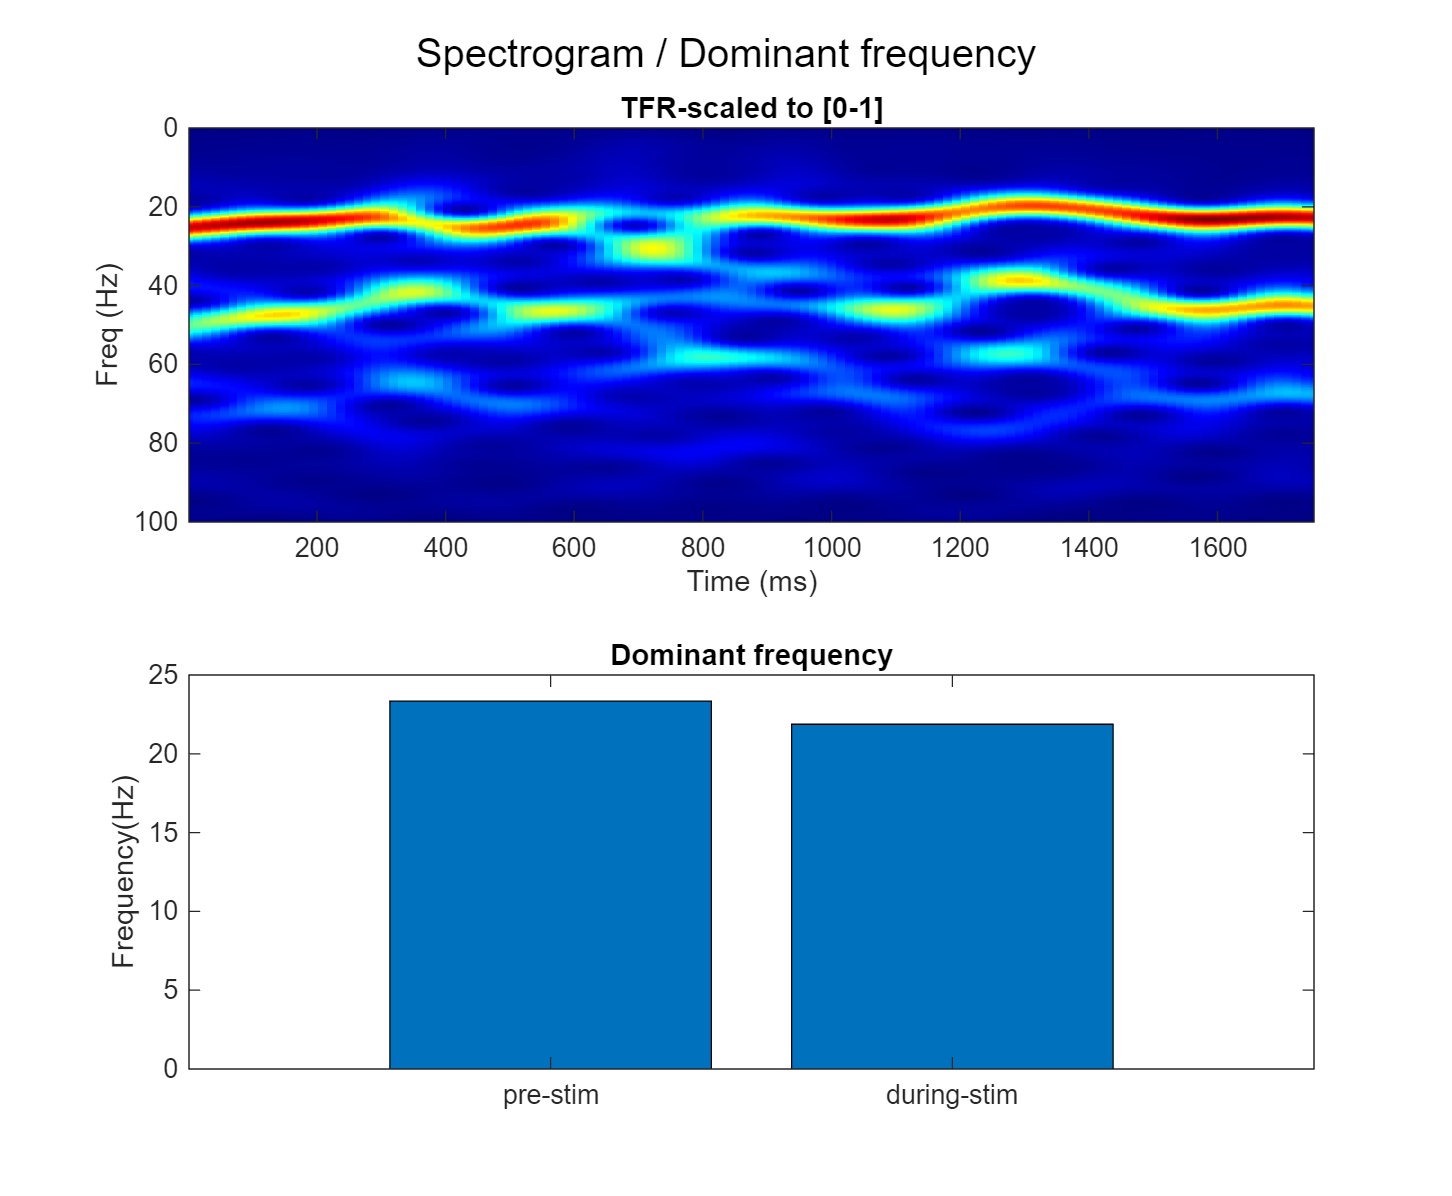

Condition Iapp = 13.3333



	->Single trial running: 
Updating parameters of dlModels/PN15/solve > 

	->Done.


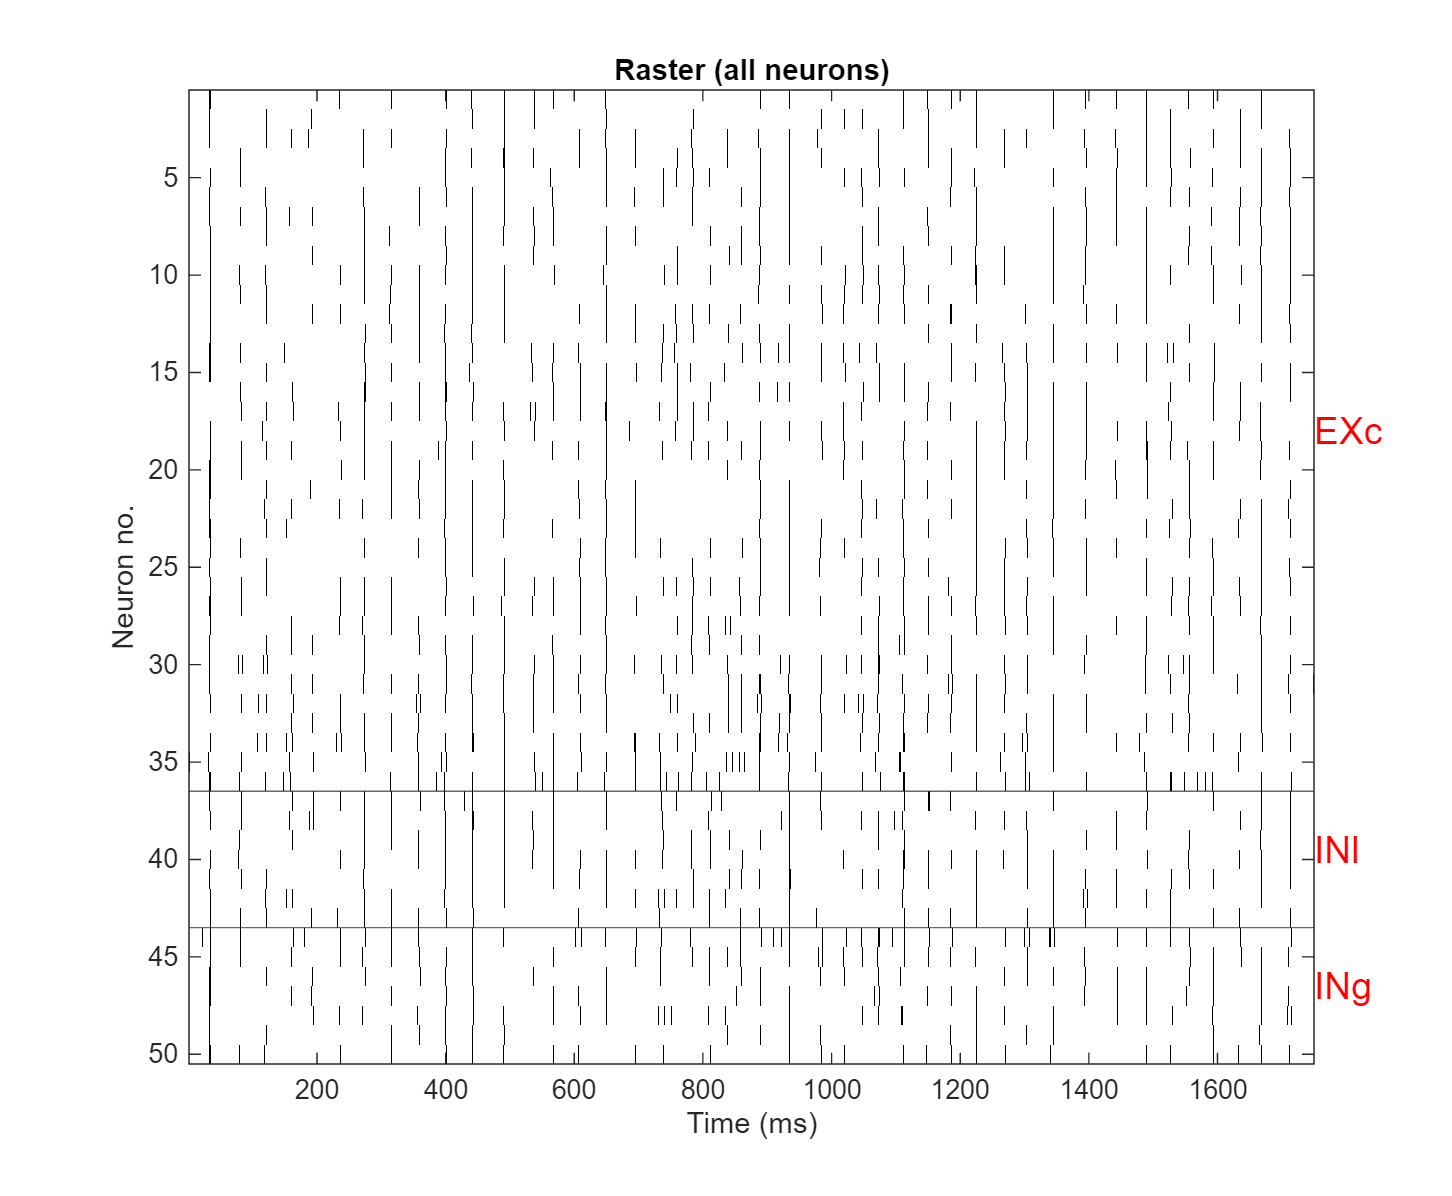

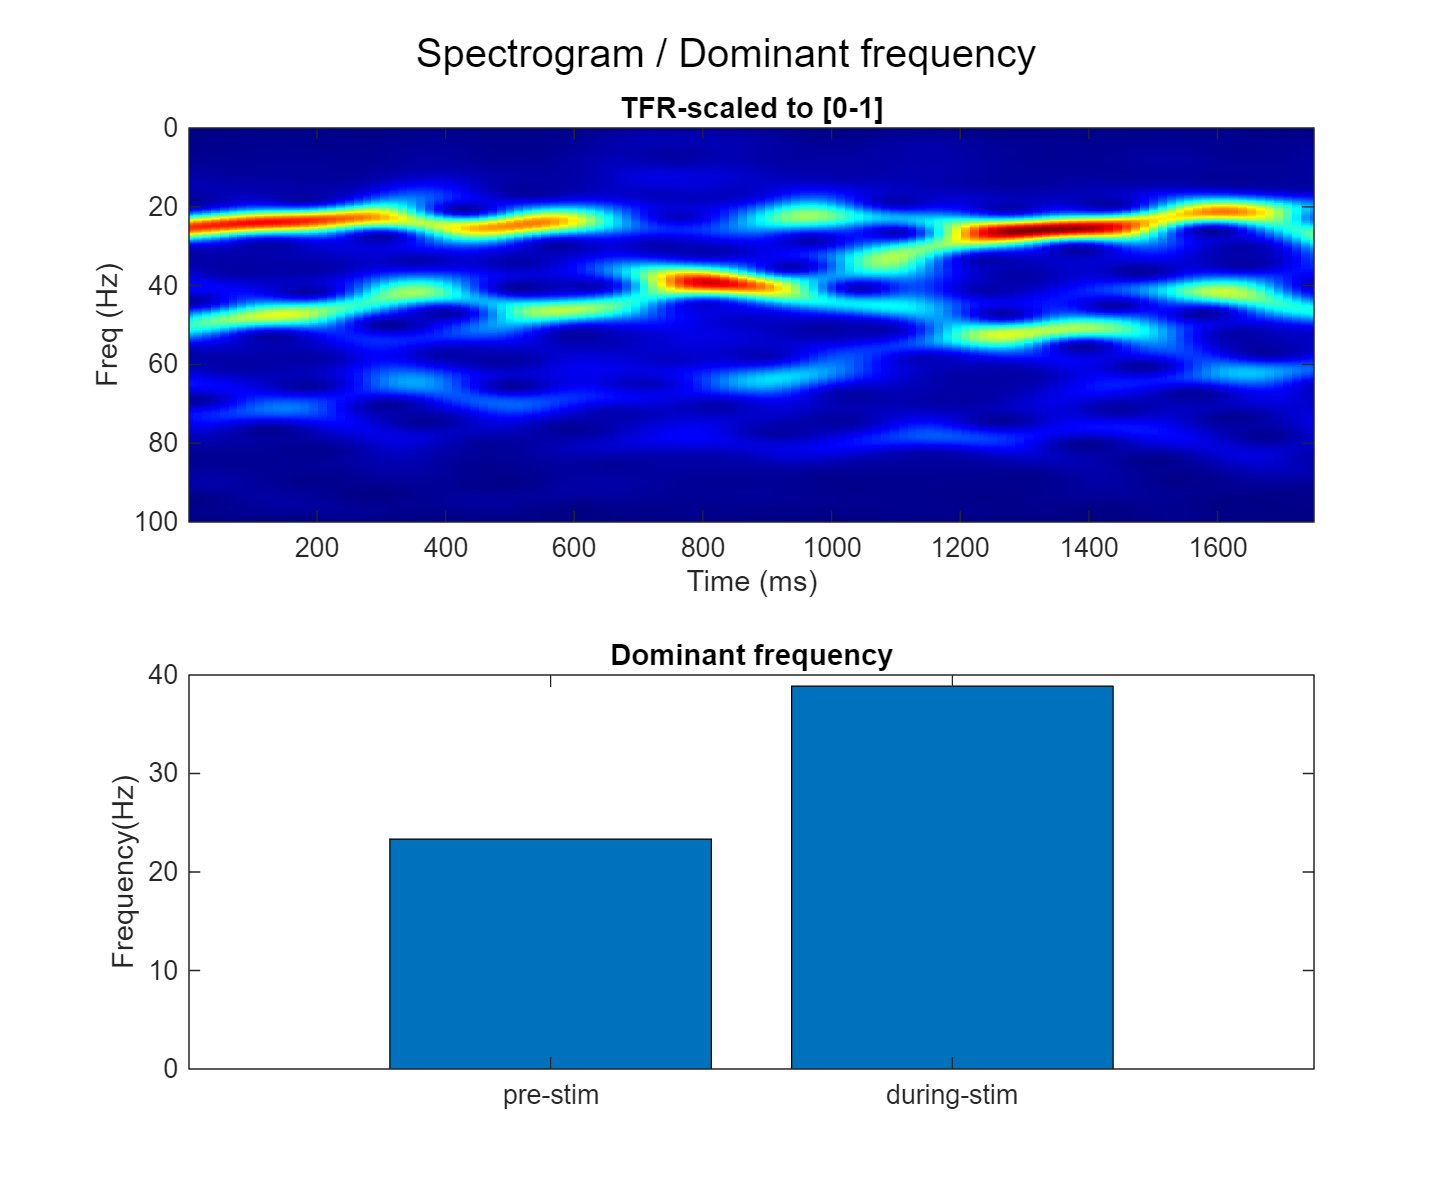

RunDuration = 1750;
ng = 3;
dlInputParameters2 = dlGradedInputs(RunDuration, 750, 1150, 20, ng);

xlims = [1 1750];
clims = [0 1.0];

for i = 1:ng%max(size(dlInputParameters, 2))

    disp("Condition Iapp = " + num2str(dlInputParameters2{i}("EXc_Iapp")));
    dl.dlRunSimulation(dlInputParameters2{i});%, dlOutputParameters);
    dl.dlRaster(xlims, -20);
    dl.dlSpectrogram(200, 1, 190, 100, xlims, clims);

end

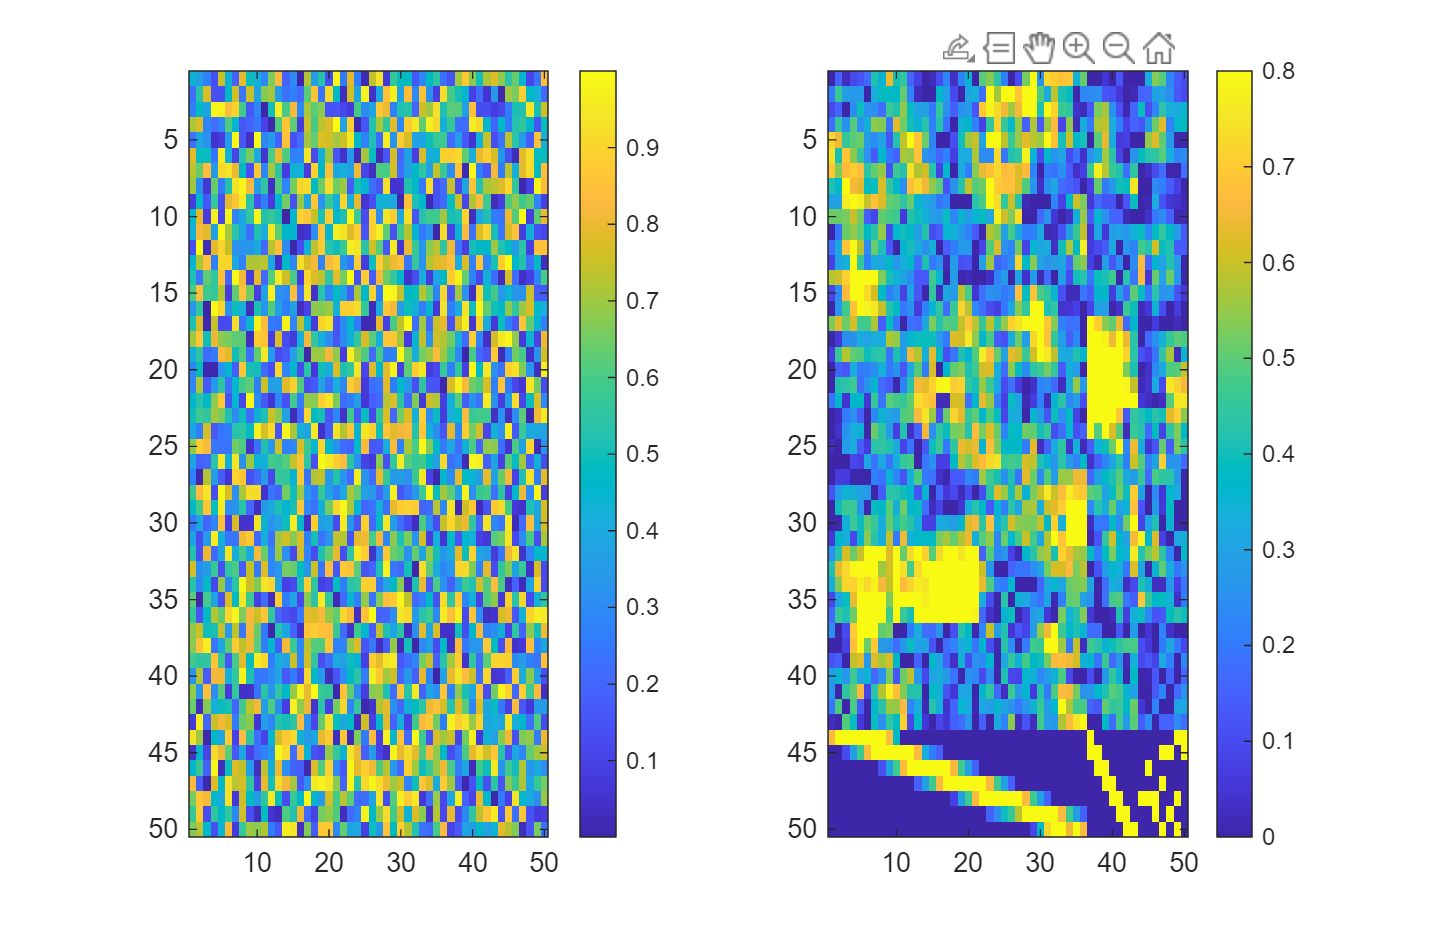

figure("Position", [0 0 1700 1100]);
subplot(1, 2, 1);
imagesc(rand([50, 50]));
colorbar();

subplot(1, 2, 2);
imx = zeros([50, 50]);
imx(1:36, 1:36) = dl.dlParams.EXc_EXc_iAMPA_netcon;
imx(1:36, 37:43) = dl.dlParams.INg_EXc_iAMPA_netcon;
imx(1:36, 44:50) = dl.dlParams.INl_EXc_iAMPA_netcon;
imx(37:43, 1:36) = dl.dlParams.EXc_INg_iGABAa_netcon;
imx(37:43, 37:43) = dl.dlParams.INg_INg_iGABAa_netcon;
imx(37:43, 44:50) = dl.dlParams.INl_INg_iGABAa_netcon;
imx(44:50, 1:36) = dl.dlParams.EXc_INl_iGABAa_netcon;
imx(44:50, 37:43) = dl.dlParams.INg_INl_iGABAa_netcon;
imx(44:50, 44:50) = dl.dlParams.INl_INl_iGABAa_netcon;

imagesc(imx);
colorbar();

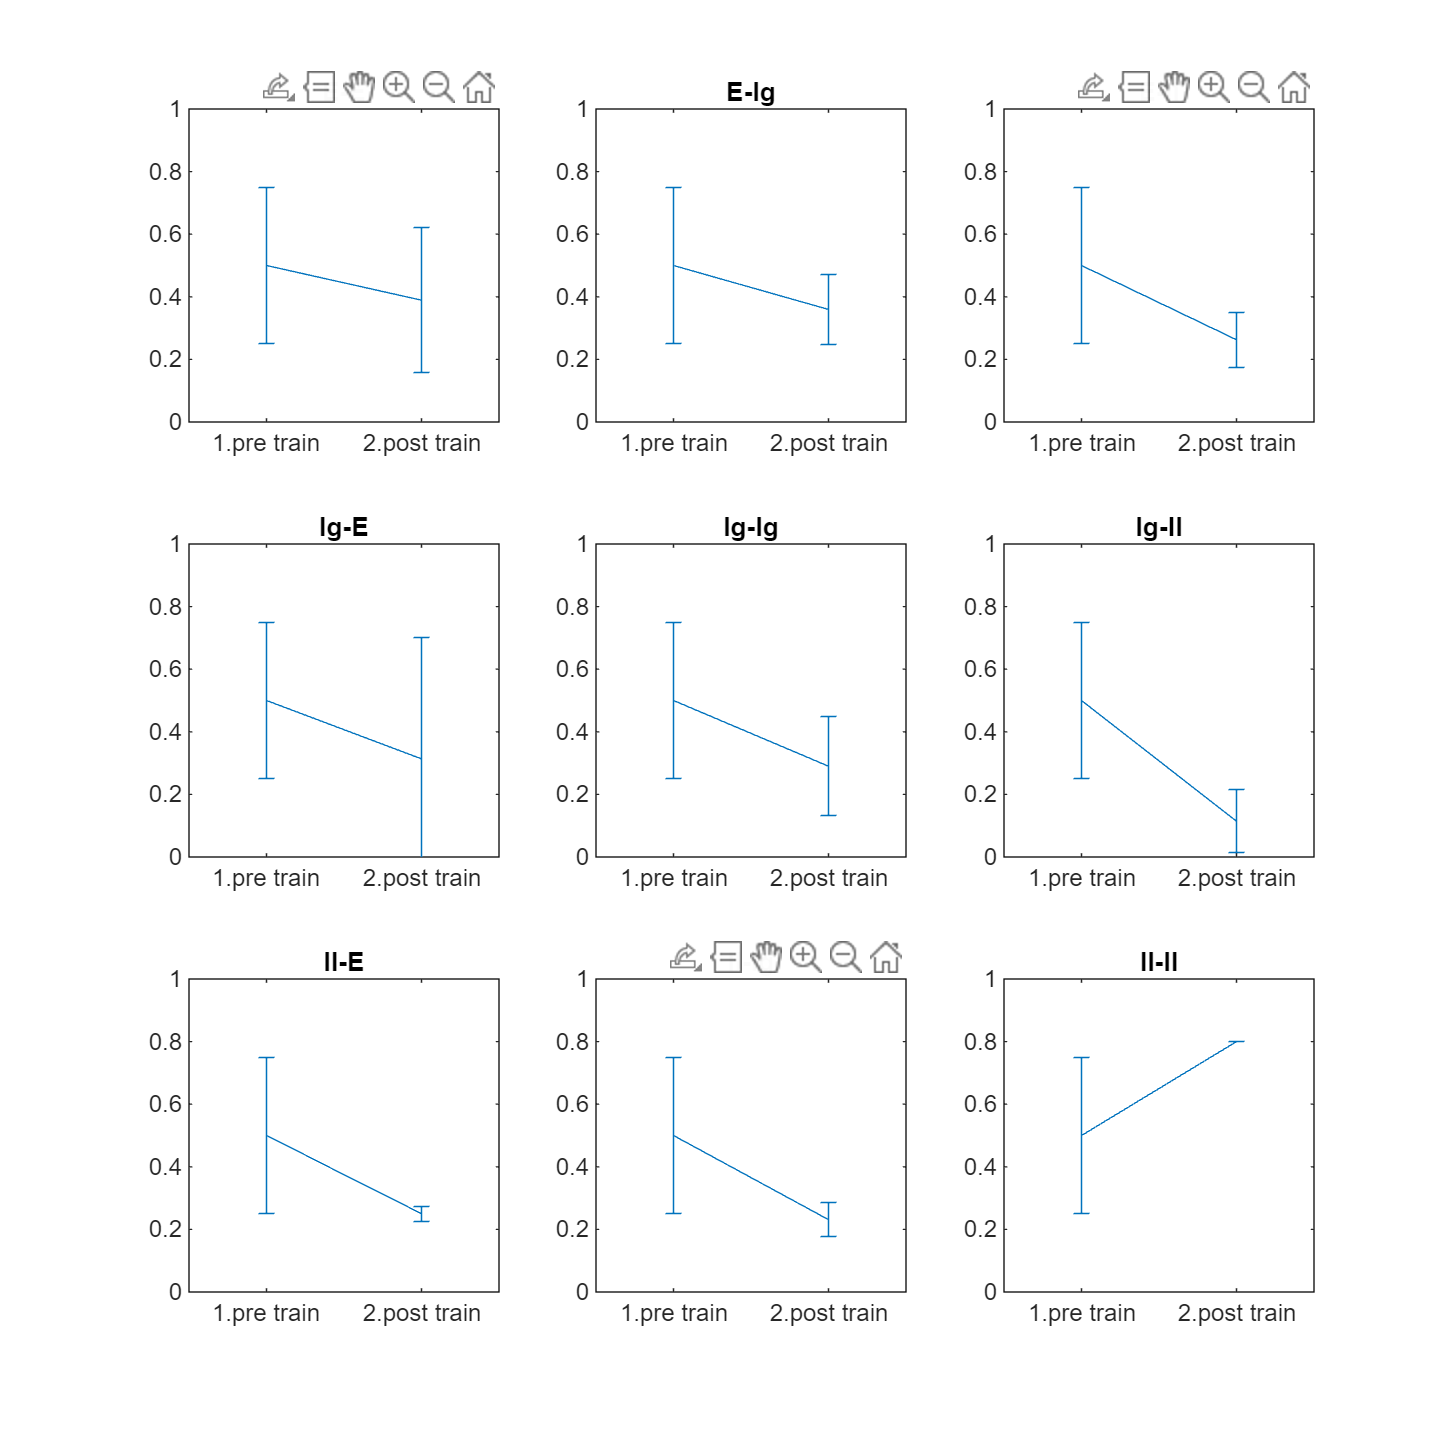

cvals = zeros(9, 2);

ex_ex = dl.dlParams.EXc_EXc_iAMPA_netcon;
cvals(1, 1) = mean(ex_ex, "all");
cvals(1, 2) = sum(std(ex_ex))/sqrt(numel(ex_ex));

ex_ing = dl.dlParams.INg_EXc_iAMPA_netcon;
cvals(2, 1) = mean(ex_ing, "all");
cvals(2, 2) = sum(std(ex_ing))/sqrt(numel(ex_ing));

ex_inl = dl.dlParams.INl_EXc_iAMPA_netcon;
cvals(3, 1) = mean(ex_inl, "all");
cvals(3, 2) = sum(std(ex_inl))/sqrt(numel(ex_inl));

ing_ex = dl.dlParams.EXc_INg_iGABAa_netcon;
cvals(4, 1) = mean(ing_ex, "all");
cvals(4, 2) = sum(std(ing_ex))/sqrt(numel(ing_ex));

ing_ing = dl.dlParams.INg_INg_iGABAa_netcon;
cvals(5, 1) = mean(ing_ing, "all");
cvals(5, 2) = sum(std(ing_ing))/sqrt(numel(ing_ing));

ing_inl = dl.dlParams.INl_INg_iGABAa_netcon;
cvals(6, 1) = mean(ing_inl, "all");
cvals(6, 2) = sum(std(ing_inl))/sqrt(numel(ing_inl));

inl_ex = dl.dlParams.EXc_INl_iGABAa_netcon;
inl_ex = inl_ex(inl_ex > 0.0);

cvals(7, 1) = mean(inl_ex, "all");
cvals(7, 2) = sum(std(inl_ex))/sqrt(numel(inl_ex));

inl_ing = dl.dlParams.INg_INl_iGABAa_netcon;
inl_ing = inl_ing(inl_ing > 0.0);
cvals(8, 1) = mean(inl_ing, "all");
cvals(8, 2) = sum(std(inl_ing))/sqrt(numel(inl_ing));

inl_inl = dl.dlParams.INl_INl_iGABAa_netcon;
inl_inl = inl_inl(inl_inl > 0.0);
cvals(9, 1) = mean(inl_inl, "all");
cvals(9, 2) = sum(std(inl_inl))/sqrt(numel(inl_inl));

clabels = ["E-E", "E-Ig", "E-Il", "Ig-E", "Ig-Ig", "Ig-Il", "Il-E", "Il-Ig", "Il-Il"];
cnt = 0;

figure("Position", [0 0 1400 1400]);

for ik = 1:9

    cnt = cnt + 1;
    subplot(3, 3, cnt);
    labelsx = categorical(["1.pre train", "2.post train"]);
    errorbar(labelsx, [0.5, cvals(cnt, 1)], [0.25, cvals(cnt, 2)]);
    title(clabels(cnt));ylim([0 1]);

end

a = struct();
a.L1.E = 10;
a.L1.PV = 1;
a.L1.CB = 2;
a.L1.CR = 3;

y1 = zeros(size(x, 1), size(x, 2), 100);
y2 = zeros(size(x, 1), size(x, 2), 100);

t_on = 1001:2000;
t_off = 5001:6000;

for i = 1:size(x, 1)

    for j = 1:size(x, 2)

        w = squeeze(x(i, j, t_on));
        y1(i, j, :) = dlSpectrum(w, 1000, 100, 100, 0);
        w = squeeze(x(i, j, t_off));
        y2(i, j, :) = dlSpectrum(w, 1000, 100, 100, 0);

    end

end

targetVspectrum1 = mean(squeeze(mean(y1, 1)), 1);
targetVspectrum2 = mean(squeeze(mean(y2, 1)), 1);
targetVspectrum1 = targetVspectrum1 - min(targetVspectrum1);
targetVspectrum2 = targetVspectrum2 - min(targetVspectrum2);

targetVspectrum1 = targetVspectrum1 / max(targetVspectrum1);
targetVspectrum2 = targetVspectrum2 / max(targetVspectrum2);

targetVspectrum1(targetVspectrum1 < 0.05) = 0.05;
targetVspectrum2(targetVspectrum2 < 0.05) = 0.05;

figure("Position", [0 0 1500 500]);
subplot(2, 1, 1);
plot(targetVspectrum1(1:100));
title("Stim on");
subplot(2, 1, 2);
plot(targetVspectrum2(1:100));
title("Stim off");

## End